# 5G NR Downlink CSI Reporting

The example shows how to compute downlink channel state information (CSI) parameters such as the channel quality indicator (CQI), precoding matrix indicator (PMI) for multiple input multiple output (MIMO) scenarios, and rank indicator (RI), as defined in TS 38.214 Section 5.2.2, over a tapped delay line (TDL) channel. The example supports computation of the CSI parameters considering type 1 single panel or type 1 multipanel codebooks.

## **Introduction**

CSI parameters are the quantities related to the state of a channel. The user equipment (UE) reports CSI parameters to the access network node (gNB) as a feedback. The CSI feedback includes several parameters, such as the CQI, the PMI with different codebook sets, and the rank indicator (RI). The UE uses channel state information reference signal (CSI-RS) to measure the CSI feedback. Upon receiving the CSI parameters, the gNB schedules downlink data transmissions (such as modulation scheme, code rate, number of transmission layers, and MIMO precoding) accordingly. The figure shows an overview of CSI-RS transmission, CSI computation and feedback, and the transmission of downlink data that is scheduled based on the CSI parameters.

     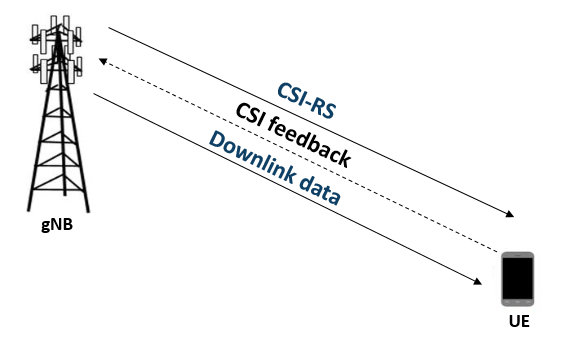

### **RI Selection**

The RI defines the number of possible transmission layers for the downlink transmission under specific channel conditions. It is also termed as the maximum number of uncorrelated paths that can be used for the downlink transmission. Other CSI parameters like the PMI and CQI are computed based on the rank provided by the RI. For given channel conditions, `hRISelect` computes the signal to interference and noise ratio (SINR) along with the PMI for all possible valid number of transmission layers. The function reports the number of transmission layers with the maximum total SINR as rank.    

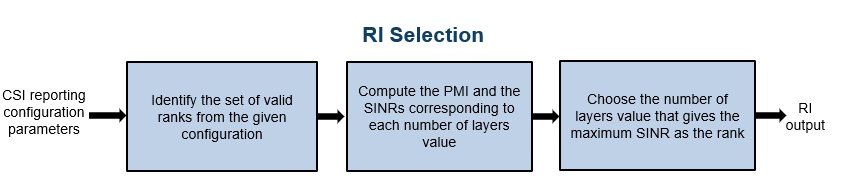

### **PMI Selection**

The PMI is a set of indices corresponding to a precoding matrix and gNB can apply this precoding matrix for the downlink data transmission. The `hDLPMISelect` selects a codebook from a set of possible codebooks, defined in TS 38.214 Tables 5.2.2.2.1-1 to 5.2.2.2.1-12 for type 1 single panel or TS 38.214 Tables 5.2.2.2.2-1 to 5.2.2.2.2-6 for type 1 multipanel, based on the codebook type, possible number of transmission layers for the downlink transmission and CSI reporting configuration parameters such as antenna panel dimensions and the codebook mode. Each codebook consists of a set of precoding matrices. For given channel conditions, the function computes SINR at the receiver side by considering all precoding matrices from the selected codebook. The function reports PMI as the set of indices (constituting the two indices set $i_1 ,i_2 \;,$ as defined in TS 38.214 Section 5.2.2.2.1 for type 1 single panel codebooks and TS 38.214 Section 5.2.2.2.2 for type 1 multipanel codebooks) corresponding to a precoding matrix, which gives the maximum SINR. The figure shows the procedure for PMI selection.

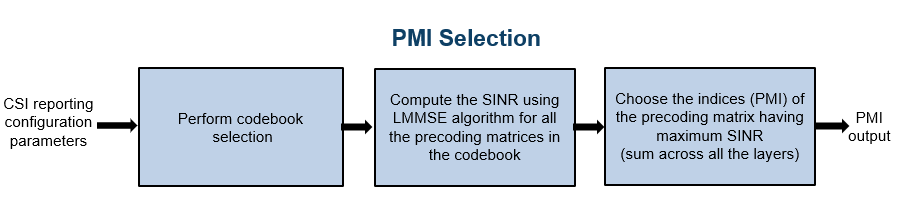

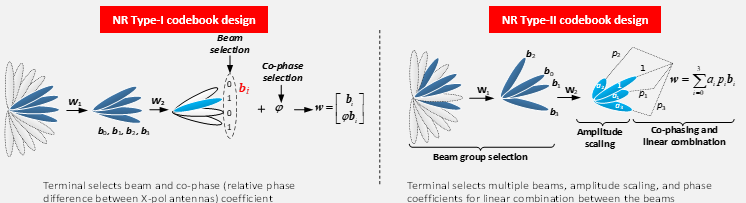

### 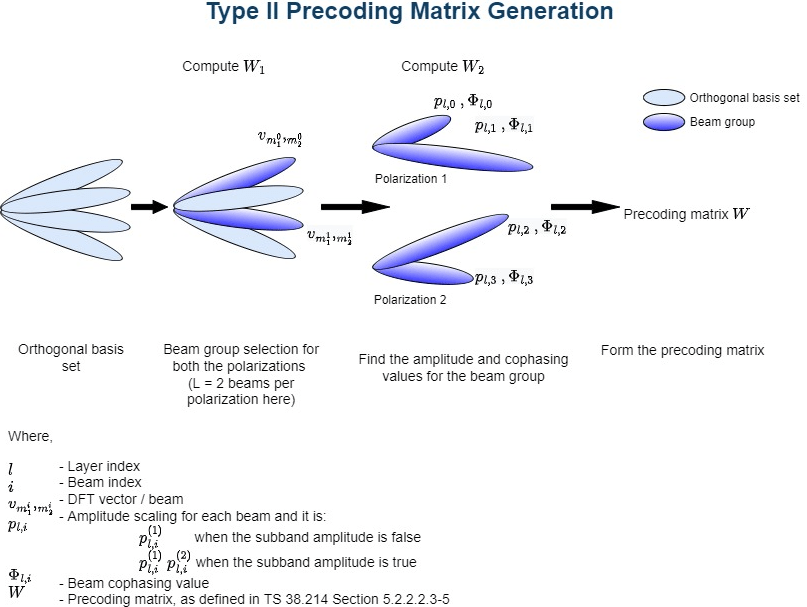

### **CQI Selection**

The CQI is an indicator of channel quality. The CQI index is a scalar value from 0 to 15. It provides the information about the highest modulation scheme and the code rate (MCS) suitable for the downlink transmission to achieve the required block error rate (BLER) for given channel conditions. 

The CSI-reference resource is a group of downlink frequency-domain and time-domain resources that are configured, as defined in TS 38.214 Section 5.2.2.5. The gNB transmits a single physical downlink shared channel (PDSCH) transport block occupying the resource blocks termed as CSI reference resource, with a combination of modulation scheme and target code rate that correspond to each CQI index. The UE selects the highest index as CQI, when the mentioned PDSCH transport block can be received with a transport block error probability not exceeding:

- 0.1 for *'cqi-Table'* as *'table1'* or *'table2'*

- 0.00001 for *'cqi-Table'* as *'table3'* 

The *'cqi-Table'* is a higher layer parameter that corresponds to the CQI versus MCS table, and SINR lookup table is computed for this table. This example uses a 0.1 BLER (corresponding to a 90 percent throughput) and *'cqi-Table'* as *'table1'* (TS 38.214 Table 5.2.2.1-2). The relationship between the CQI indices, the modulation scheme, and the code rate (from which the transport block size is derived) is described in TS 38.214 Tables 5.2.2.1-2 to 5.2.2.1-4.

The `hCQISelect` function computes the CQI value by considering the SINR values that correspond to the reported PMI, using the precalculated lookup table of the CQI index versus ${\textrm{SINR}}_i$, as a reference. The function maps the SINR values across all layers (corresponding to the reported PMI) to each codeword. For each codeword, the function compares the respective SINR with the ${\textrm{SINR}}_i$ values from the table and then, selects the CQI value against the maximum SINR, which is less than the codeword SINR. The CQI value is set such that the BLER is less than or equal to 0.1 when operated at ${\textrm{SINR}}_i$. If a CQI index of 1 does not satisfy the BLER condition, then the CQI index is set as 0. The figure shows the procedure for CQI selection.

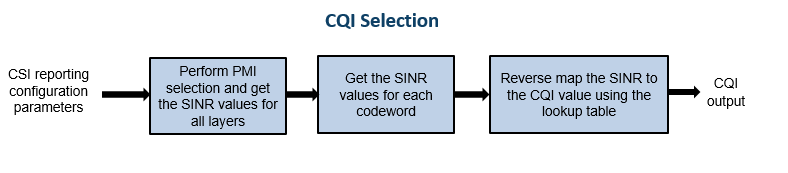

#### **CQI Versus SINR Table**

To create the lookup tables, update the `NewRadioPDSCHThroughputExample` to configure the CSI reference resource, as defined in TS 38.214 Section 5.2.2.5. Perform simulations for PDSCH throughput by considering the modulation scheme and code rate corresponding to each CQI, certain channel conditions and across a finite range of SINR values with zero interference. Map the SINR value observed at the receiver, where the target BLER is achieved, against each CQI index. The figure shows the procedure for CQI versus SINR table creation.

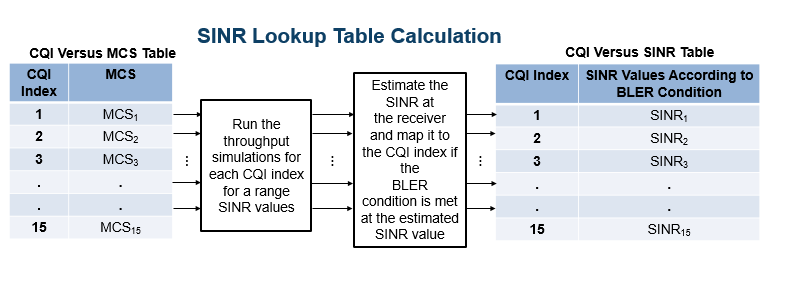

### **Outline of Example**

This example shows how to compute the CQI and PMI indices for a 4-by-4 MIMO scenario over a TDL channel with delay profile TDL-C, a delay spread of 300e-9 seconds, and a maximum Doppler shift of 50 Hz. It compares the time-domain and frequency-domain variations of CQI values against the time-domain and frequency-domain variations of SINR values for both practical and perfect channel estimation scenarios. The example also highlights the time-domain and frequency-domain variations of the PMI values for practical and perfect channel estimation scenarios corresponding to the reported rank.

## **Simulation Length and SNR Point**

Set the length of the simulation in terms of the number of 10 ms frames. The SNR (SINR with zero interference) is defined per resource element (RE) and applies to each receive antenna. For an explanation of the SNR definition that this example uses, see [SNR Definition used in Link Simulations](docid:5g_ug#mw_37cef3ca-2f4b-433d-8d68-117a881ca5fd).

simParameters = struct();       % Clear simParameters variable to contain all key simulation parameters 
simParameters.NFrames = 2;      % Number of 10 ms frames
simParameters.SNRIn = [-10 10]; % SNR range (dB)
SNRdB = 10;  % SNR in dB

simParameters.PerfectChannelEstimator = false;
simParameters.DisplaySimulationInformation = true;
simParameters.DisplayDiagnostics = false;

## **Carrier, BWP and PDSCH Configuration**

Create a carrier configuration object representing a 10 MHz carrier with a subcarrier spacing of 15 kHz.

% SCS carrier parameters
simParameters.Carrier = nrCarrierConfig;         % Carrier resource grid configuration
simParameters.Carrier.NSizeGrid = 52;            % Bandwidth in number of resource blocks
simParameters.Carrier.SubcarrierSpacing = 15;    % 15, 30, 60, 120 (kHz)
simParameters.Carrier.CyclicPrefix = 'Normal';   % 'Normal' or 'Extended' (Extended CP is relevant for 60 kHz SCS only)
simParameters.Carrier.NCellID = 1;               % Cell identity

Configure the size of the bandwidth part (BWP) and the start of the BWP relative to common resource block 0 (CRB 0).

NStartBWP = 0;
NSizeBWP = 52;

Specify a full-band slot-wise PDSCH transmission and reserve the first 2 OFDM symbols.

simParameters.PDSCH = nrPDSCHConfig;      % This PDSCH definition is the basis for all PDSCH transmissions in the simulation

% Define PDSCH time allocation in a slot
simParameters.PDSCH.MappingType = "A"; % PDSCH mapping type ('A'(slot-wise),'B'(non slot-wise))
symAlloc = [2 simParameters.Carrier.SymbolsPerSlot-2];  % Starting symbol and number of symbols of each PDSCH allocation
simParameters.PDSCH.SymbolAllocation = symAlloc;

% Define PDSCH frequency resource allocation per slot to be full grid 
simParameters.PDSCH.PRBSet = 0:simParameters.Carrier.NSizeGrid-1;

% Scrambling identifiers
simParameters.PDSCH.NID = simParameters.Carrier.NCellID;
simParameters.PDSCH.RNTI = 1;

Specify the DM-RS configuration, as defined in TS 38.211 Section 7.4.1.1. The DM-RS port set is dynamic and based on CSI feedback (RI).

simParameters.PDSCH.DMRS.DMRSTypeAPosition       = 2; % Mapping type A only. First DM-RS symbol position (2,3)
simParameters.PDSCH.DMRS.DMRSLength              = 1; % Number of front-loaded DM-RS symbols (1(single symbol),2(double symbol))
simParameters.PDSCH.DMRS.DMRSAdditionalPosition  = 2; % Additional DM-RS symbol positions (max range 0...3)
simParameters.PDSCH.DMRS.DMRSConfigurationType   = 2; % DM-RS configuration type (1,2)
simParameters.PDSCH.DMRS.NumCDMGroupsWithoutData = 3; % CDM groups without data (1,2,3)

Specify additional simulation parameters for the DL-SCH and PDSCH. Set the frequency granularity of the MIMO precoder, as defined in TS 38.214 Section 5.1.2.3, the modulation and coding scheme table, as defined in TS 38.214 Section 5.1.3.1, and the overhead for transport block size calculation. Set `XOverhead` to empty (`[]`) for automatic selection based on the CSI-RS allocated REs.

simParameters.PDSCHExtension = struct();
simParameters.PDSCHExtension.PRGBundleSize = 4; % 2, 4, or [] to signify "wideband"
simParameters.PDSCHExtension.MCSTable      = 'Table1'; % 'Table1',...,'Table4'
simParameters.PDSCHExtension.XOverhead     = [ ]; % 0, 6, 12, 18, or [] for automatic selection.

Configure the LDPC decoding algorithm and maximum LDPC iterations. The available decoding algorithms are '`Belief propagation`', '`Layered belief propagation`', '`Normalized min-sum`', and '`Offset min-sum`'.

simParameters.PDSCHExtension.LDPCDecodingAlgorithm = "Normalized min-sum";
simParameters.PDSCHExtension.MaximumLDPCIterationCount = 6;

## **Antenna Pannel Configurations**

The MIMO precoding codebooks defined in TS 38.214 Section 5.2.2.2 restrict the values of *Ng*, *N*1, and *N*2 that 5G NR supports. To configure single-input single-output (SISO) transmissions with single-polarized antenna elements, set the panel dimensions to [1 1]. The receiver panel dimensions are not limited by the codebooks.

simParameters.TransmitAntennaArray.NumPanels        = 1; % Number of panels in horizontal dimension (Ng)
simParameters.TransmitAntennaArray.PanelDimensions  = [2 2]; % Number of columns and rows in a panel (N1, N2)
simParameters.ReceiveAntennaArray.NumPanels         = 1; % Number of panels in horizontal dimension (Ng)
simParameters.ReceiveAntennaArray.PanelDimensions   = [2 1];                % Number of columns and rows in a panel (N1, N2)

Due to polarization, the overall number of antennas is 2×*N*1×*N*2×*Ng*.

simParameters.NTxAnts = numAntennaElements(simParameters.TransmitAntennaArray);
simParameters.NRxAnts = numAntennaElements(simParameters.ReceiveAntennaArray);

Validate the CSI-RS configuration object.

## **CSI-RS Configuration**

Create a CSI-RS configuration object representing a non-zero-power CSI-RS (NZP-CSI-RS) resource set with a set of NZP-CSI-RS resources. Make sure that the NZP-CSI-RS resources that are configured in this example have the same code division multiplexing (CDM) types and the same number of CSI-RS ports, as defined in TS 38.214 Section 5.2.2.3.1. 

simParameters.CSIRS = nrCSIRSConfig;
simParameters.CSIRS.CSIRSType = 'nzp'; % 'nzp','zp'
simParameters.CSIRS.RowNumber = 6; % 1...18
simParameters.CSIRS.NumRB = simParameters.Carrier.NSizeGrid - simParameters.CSIRS.RBOffset;
simParameters.CSIRS.CSIRSPeriod = [10 0];
simParameters.CSIRS.SymbolLocations = 4;
simParameters.CSIRS.SubcarrierLocations = [0,3,6,9];
simParameters.CSIRS.Density = 'one';

disp(['Number of CSI-RS ports: ' num2str(simParameters.CSIRS.NumCSIRSPorts) '.'])

Number of CSI-RS ports: 8.



% csirs = nrCSIRSConfig;
% csirs.CSIRSType = {'nzp','nzp','nzp'};
% csirs.RowNumber = [8 8 8];  % SinglePanel: [4 4 4]; MultiPanel: [8 8 8]
% csirs.NumRB = 52;
% csirs.RBOffset = 0;
% csirs.CSIRSPeriod = [4 0];
% csirs.SymbolLocations = {0, 0, 0};
% csirs.SubcarrierLocations = {[0,2], [4,6], [8,10]}; % SinglePanel: One location per cell element; MultiPanel: Npanels locations per cell element
% csirs.Density = {'one','one','one'};


csirsCDMLengths = getCSIRSCDMLengths(simParameters.CSIRS);

% Check that the number of CSI-RS ports and transmit antenna elements match
% and the consistency of multiple CSI-RS resources
validateCSIRSConfig(simParameters.Carrier,simParameters.CSIRS,simParameters.NTxAnts);

## **CSI Feedback Configurations**

simParameters.CSIReportMode = 'RI-PMI-CQI'; % 'RI-PMI-CQI','AI CSI compression','Perfect CSI'

simParameters.CSIReportConfig = struct();
simParameters.CSIReportConfig.Period = [5 0];  % Peridocity and offset of the CSI report in slots

simParameters.CSIReportConfig.CQITable          = "Table1"; % 'Table1','Table2','Table3'
simParameters.CSIReportConfig.CQIMode           = 'Wideband'; % 'Wideband','Subband'
simParameters.CSIReportConfig.PMIMode           = 'Subband'; % 'Wideband','Subband'
simParameters.CSIReportConfig.CodebookType      = 'Type1SinglePanel'; % 'Type1SinglePanel','Type1MultiPanel','Type2'
simParameters.CSIReportConfig.SubbandSize       = 4; % Subband size in RB (4,8,16,32)
simParameters.CSIReportConfig.CodebookMode      = 1; % 1,2
simParameters.CSIReportConfig.RIRestriction     = [];                   % Empty for no rank restriction  
simParameters.CSIReportConfig.NumberOfBeams     = 2; % 2,3,4. Only for Type II codebooks
simParameters.CSIReportConfig.PhaseAlphabetSize = 8; % 4,8. Only for Type II codebooks
simParameters.CSIReportConfig.SubbandAmplitude  = true;                  % true/false. Only for Type II codebooks
simParameters.CSIReportConfig.NStartBWP         = [];                   % Empty to signal the entire carrier
simParameters.CSIReportConfig.NSizeBWP          = [];                   % Empty to signal the entire carrier

% Configure the CSI report with the antenna panel dimensions specified
simParameters.CSIReportConfig.PanelDimensions = getCSIReportPanelDimensions(simParameters.TransmitAntennaArray,simParameters.CSIReportConfig.CodebookType);

## **CSI Reporting Configuration**

Specify the parameters required for the CQI, PMI, and RI computation as a structure with fields:

- `NSizeBWP`: Size of the BWP in terms of the number of physical resource blocks (PRBs)

- `NStartBWP`: Starting PRB index of the BWP relative to CRB 0

- `CodebookType`: The type of codebooks according to which the CSI parameters must be computed (`'Type1SinglePanel'`, `'Type1MultiPanel'`)

- `PanelDimensions`: The antenna panel dimensions corresponding to the `CodebookType` field. 

              If `CodebookType` is configured as `'Type1SinglePanel'`, the panel dimensions are configured as [N1 N2] according to TS 38.214 Table 5.2.2.2.1-2, as shown in the figure

               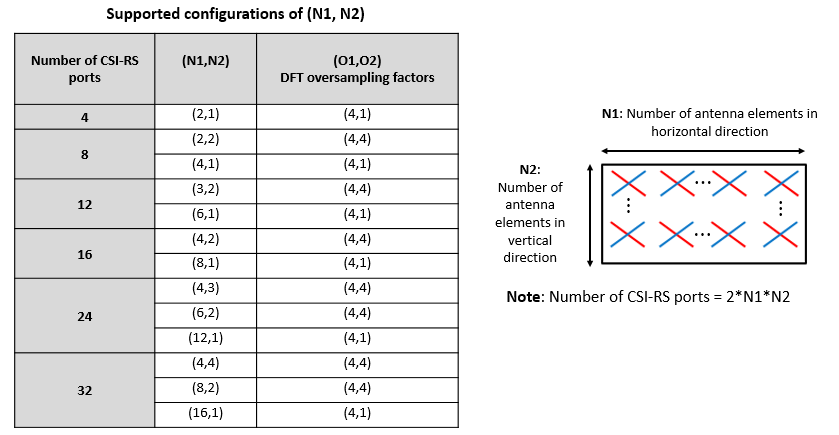

             If `CodebookType` is configured as '`Type1MultiPanel'`, the panel dimensions are configured as [Ng N1 N2] according to TS 38.214 Table 5.2.2.2.2-1, as shown in the figure

                 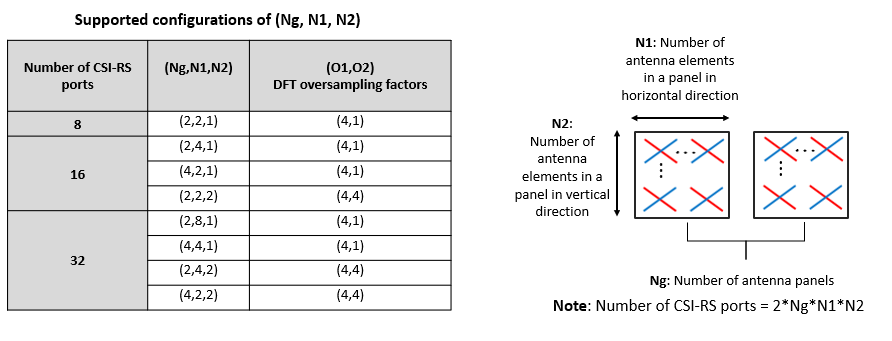

- `CQIMode`: The mode of CQI reporting (`'Subband'`, `'Wideband'`)

- `PMIMode`: The mode of PMI reporting (`'Subband'`, `'Wideband'`)

- `SubbandSize`: The size of the subband, as defined in TS 38.214 Table 5.2.1.4-2 (required only when `CQIMode` or `PMIMode` is `'Subband'`)

- `PRGSize`: The precoding resource block group (PRG) size for the CQI calculation (required only when the reporting must be done for the report quantity *'cri-RI-i1-CQI'* and `CodebookType` is configured as `'Type1SinglePanel'`, as defined in TS 38.214 Section 5.2.1.4.2)

- `CodebookMode`: The codebook mode according to which the codebooks are derived. When the `CodebookType` is configured as `'Type1SinglePanel'`, this field is required only when the number of transmission layers is 1 or 2 and the number of CSI-RS ports is greater than 2. 

- `CodebookSubsetRestriction`: Restriction parameter pertaining to the codebook index set $i_1$, that is, $v_{\textrm{lm}}$ or ${\overset{~}{v} }_{\textrm{lm}}$ restriction parameter, as defined in TS 38.214 Section 5.2.2.2.1. This field denotes the set of $i_1$ indices ($\left\lbrack i_{11\;} ,\;i_{12\;\;} \right\rbrack$) that are restricted from the consideration for the PMI computation.

- `i2Restriction`: Restriction parameter pertaining to the codebook index $i_2$. This field denotes the set of $i_2$ indices that are restricted from the consideration for the PMI computation (applicable only when `CodebookType` is `'Type1SinglePanel'`).

- `RIRestriction`: Restriction parameter pertaining to the rank indicator, which implies the set of ranks that are restricted from usage for the RI computation. 

% Configure CSI reporting configuration parameters
reportConfig.NStartBWP = NStartBWP;
reportConfig.NSizeBWP = NSizeBWP;
reportConfig.CodebookType =  'Type1MultiPanel'    %'Type1SinglePanel', 'Type1MultiPanel', 'Type2', 'eType2'

reportConfig = struct with fields:
                    NStartBWP: 0
                     NSizeBWP: 52
                 CodebookType: 'Type1MultiPanel'
              PanelDimensions: [2 2 1]
                      CQIMode: 'Wideband'
                      PMIMode: 'Subband'
                  SubbandSize: 4
                      PRGSize: []
                 CodebookMode: 1
    CodebookSubsetRestriction: []
                i2Restriction: []
                RIRestriction: []
                     CQITable: "Table1"


reportConfig.PanelDimensions = [2 2 1]; % use 2 dimensions for SinglePanel; and 3 dimensions for MultiPanel
reportConfig.CQIMode = 'Wideband';   % 'Subband'; 'Wideband'
reportConfig.PMIMode = 'Subband';   % 'Subband'; 'Wideband'
reportConfig.SubbandSize = 4;
reportConfig.PRGSize = [];
reportConfig.CodebookMode = 1;
reportConfig.CodebookSubsetRestriction = [];
reportConfig.i2Restriction = [];
reportConfig.RIRestriction = [];
reportConfig.CQITable = "Table1"; % 'Table1','Table2','Table3'

Configure the CSI processing delay in slots. For the UE, this delay is the number of time slots between the reception of the CSI-RS and the availability of the CSI feedback. For the gNodeB, the delay is the number of time slots between the reception of the CSI report and the transmission using the recommended CSI.

simParameters.UEProcessingDelay = 7;
simParameters.BSProcessingDelay = 1;

## **Propagation Channel Model Configuration**

Consider a TDL channel with delay profile TDL-C, a delay spread of 300e-9 seconds, and a maximum Doppler shift of 50 Hz.

% Create channel object
simParameters.DelayProfile = 'TDL-C';   % 'CDL-A',...,'CDL-E','TDL-A',...,'TDL-E'
simParameters.DelaySpread = 300e-9;     % s
simParameters.MaximumDopplerShift = 50;  % Hz
simParameters.Channel = createChannel(simParameters);

Get the maximum number of delayed samples by a channel multipath component. The maximum number of delayed samples is calculated from the channel path with the largest delay and the implementation delay of the channel filter. The number of samples that correspond to the maximum channel delay is required later to flush the channel filter to obtain the received signal.

% chInfo = info(simParameters.Channel);
% maxChDelay = ceil(max(chInfo.PathDelays*simParameters.Channel.SampleRate)) + chInfo.ChannelFilterDelay;

## **Processing Loop**

For each slot, generate the CSI-RS, transmit through the channel, and then process at the receiver side to compute the CQI, PMI, and RI values. Follow the steps for the transmit to receive end processing for each slot.

- **Generate the resource grid:** Generate the slot grid that is populated with the CSI-RS and map the slot grid from CSI-RS ports to transmit antennas.

- **Generate the waveform:** Perform orthogonal frequency division multiplexing (OFDM) modulation on the generated grid by using the `nrOFDMModulate` function.

- **Model and apply a noisy channel:** Pass the waveform through a TDL-C fading channel, and then add the additive white Gaussian noise (AWGN). The SNR is defined per RE and applies to each receive antenna.

- **Perform timing synchronization and OFDM demodulation:** For practical synchronization, correlate the received waveform with the CSI-RS. For perfect synchronization, use the path gains and path filters of the channel are used. The synchronized signal is then OFDM demodulated with the `nrOFDMDemodulate` function.

- **Perform channel estimation:** For practical channel estimation, use the CSI-RS. For perfect channel estimation, use the path gains, the path filters, and the sample times of channel snapshots.

- **Compute CQI, PMI and RI values:** Compute CQI, PMI, and RI values using practical and perfect channel estimations.

% Array to store the maximum throughput for all SNR points
maxThroughput = zeros(length(simParameters.SNRIn),1); 
% Array to store the simulation throughput for all SNR points
simThroughput = zeros(length(simParameters.SNRIn),1);

% Cell array to store CSI reports per SNR point
CSIReport = {};

for snrIdx = 1:numel(simParameters.SNRIn)
% parfor snrIdx = 1:numel(simParameters.SNRIn)
% To reduce the total simulation time, you can execute this loop in
% parallel by using the Parallel Computing Toolbox. Comment out the 'for'
% statement and uncomment the 'parfor' statement.
    
    % Reset the random number generator for repeatability
    rng(0,"twister");

    % Display simulation information at this SNR point
    displaySNRPointProgress(simParameters,snrIdx);

    % Take full copies of the simulation-level parameter structures so that
    % they are not PCT broadcast variables when using parfor
    simParamLocal = simParameters;

    % Set up the transmitter, propagation channel, receiver, and CSI
    % feedback configuration parameters.
    [carrier,encodeDLSCH,pdsch,pdschextra,csirs,wtx] = setupTransmitter(simParamLocal);
    [channel,maxChDelay,N0] = setupChannel(simParamLocal,snrIdx);
    [decodeDLSCH,pathFilters,timingOffset] = setupReceiver(simParamLocal);
    csiFeedbackOpts = getCSIFeedbackOptions(simParamLocal,snrIdx);

    % Obtain an initial CSI report based on perfect channel estimates that
    % the Tx can use to adapt the transmission parameters.
    csiReports = initialCSIReport(simParamLocal,snrIdx,carrier,csirs,channel,csiFeedbackOpts);
    csiAvailableSlots = 0;

    % Total number of slots in the simulation period
    NSlots = simParamLocal.NFrames * carrier.SlotsPerFrame;

    % Loop over the entire waveform length
    for nslot = 0:NSlots-1

        % Update the carrier slot numbers for new slot
        carrier.NSlot = nslot;

        % Use new CSI report to configure the number of layers and
        % modulation of the PDSCH and target code rate of the DL-SCH if
        % there is a new report available.
        [isNewReport,repIdx] = ismember(nslot,csiAvailableSlots);
        if isNewReport
            [pdsch.Modulation,pdschextra.TargetCodeRate,wtx] = hCSIDecode(carrier,pdsch,pdschextra,csiReports(repIdx),csiFeedbackOpts);
            pdsch.NumLayers = size(wtx,1);
            encodeDLSCH.TargetCodeRate = pdschextra.TargetCodeRate;
        end

        % Create an OFDM resource grid for a slot
        dlGrid = nrResourceGrid(carrier,csirs.NumCSIRSPorts);

        % CSI-RS mapping to the slot resource grid
        [csirsInd,csirsInfo] = nrCSIRSIndices(carrier,csirs);
        csirsSym = nrCSIRS(carrier,csirs);
        dlGrid(csirsInd) = csirsSym;
        csirsTransmission = ~isempty(csirsInd);

        % PDSCH reserved REs for CSI-RS
        pdsch.ReservedRE = csirsInd-1; % 0-based indices
        
        % PDSCH generation
        % Calculate the transport block sizes for the transmission in the slot
        [pdschIndices,pdschIndicesInfo] = nrPDSCHIndices(carrier,pdsch);
        trBlkSizes = nrTBS(pdsch.Modulation,pdsch.NumLayers,numel(pdsch.PRBSet),pdschIndicesInfo.NREPerPRB,pdschextra.TargetCodeRate,pdschextra.XOverhead);

        % Transport block generation
        for cwIdx = 1:pdsch.NumCodewords
            % New data for current codeword then create a new DL-SCH transport block
            trBlk = randi([0 1],trBlkSizes(cwIdx),1);
            setTransportBlock(encodeDLSCH,trBlk,cwIdx-1);
            resetSoftBuffer(decodeDLSCH,cwIdx-1);
        end

        % Encode the DL-SCH transport blocks
        RV = zeros(1,pdsch.NumCodewords);
        codedTrBlocks = encodeDLSCH(pdsch.Modulation,pdsch.NumLayers, ...
            pdschIndicesInfo.G,RV);

        % PDSCH modulation and precoding
        pdschSymbols = nrPDSCH(carrier,pdsch,codedTrBlocks);
        [pdschAntSymbols,pdschAntIndices] = nrPDSCHPrecode(carrier,pdschSymbols,pdschIndices,wtx);
        dlGrid(pdschAntIndices) = pdschAntSymbols;        

        % PDSCH DM-RS precoding and mapping
        dmrsSymbols = nrPDSCHDMRS(carrier,pdsch);
        dmrsIndices = nrPDSCHDMRSIndices(carrier,pdsch);
        [dmrsAntSymbols,dmrsAntIndices] = nrPDSCHPrecode(carrier,dmrsSymbols,dmrsIndices,wtx);
        dlGrid(dmrsAntIndices) = dmrsAntSymbols;

        % OFDM modulation
        txWaveform = nrOFDMModulate(carrier,dlGrid);

        % Pass data through channel model. Append zeros at the end of the
        % transmitted waveform to flush channel content. These zeros take
        % into account any delay introduced in the channel.
        txWaveform = [txWaveform; zeros(maxChDelay,size(txWaveform,2))]; %#ok<AGROW>
        [rxWaveform,pathGains,sampleTimes] = channel(txWaveform);
        
        % Add AWGN to the received time-domain waveform
        noise = N0*complex(randn(size(rxWaveform)),randn(size(rxWaveform)));
        rxWaveform = rxWaveform + noise;

        if (simParamLocal.PerfectChannelEstimator)
            % Perfect synchronization. Use information provided by the
            % channel to find the strongest multipath component
            pathFilters = getPathFilters(channel);
            [timingOffset,mag] = nrPerfectTimingEstimate(pathGains,pathFilters);
        else
            % Practical synchronization. Correlate the received waveform
            % with the PDSCH DM-RS to obtain the timing offset and
            % correlation magnitude. The receiver updates the timing offset
            % only when the correlation magnitude is high.
            [t,mag] = nrTimingEstimate(carrier,rxWaveform,dmrsIndices,dmrsSymbols); 
            timingOffset = hSkipWeakTimingOffset(timingOffset,t,mag);
            % Display a warning if the estimated timing offset exceeds the
            % maximum channel delay
            if timingOffset > maxChDelay
                warning(['Estimated timing offset (%d) is greater than the maximum channel delay (%d).' ...
                    ' This will result in a decoding failure. This may be caused by low SNR,' ...
                    ' or not enough DM-RS symbols to synchronize successfully.'],timingOffset,maxChDelay);
            end
        end
        rxWaveform = rxWaveform(1+timingOffset:end,:);

        % Perform OFDM demodulation on the received data to recreate the
        % resource grid, including padding in the event that practical
        % synchronization results in an incomplete slot being demodulated
        rxGrid = nrOFDMDemodulate(carrier,rxWaveform);
        [K,L,R] = size(rxGrid);
        if (L < carrier.SymbolsPerSlot)
            rxGrid = cat(2,rxGrid,zeros(K,carrier.SymbolsPerSlot-L,R));
        end

        if (simParamLocal.PerfectChannelEstimator)
            % Perfect channel estimation, using the value of the path gains
            % provided by the channel. This channel estimate does not
            % include the effect of transmitter precoding
            Hest = nrPerfectChannelEstimate(carrier,pathGains,pathFilters,timingOffset,sampleTimes);

            % Get perfect noise estimate (from the noise realization)
            noiseGrid = nrOFDMDemodulate(carrier,noise(1+timingOffset:end ,:));
            noiseEst = var(noiseGrid(:));

            % Get PDSCH resource elements from the received grid and 
            % channel estimate
            [pdschRx,pdschHest,~,pdschHestIndices] = nrExtractResources(pdschIndices,rxGrid,Hest);

            % Apply precoding to channel estimate
            pdschHest = nrPDSCHPrecode(carrier,pdschHest,pdschHestIndices,permute(wtx,[2 1 3]));
        else
            % Practical channel estimation between the received grid and
            % each transmission layer, using the PDSCH DM-RS for each
            % layer. This channel estimate includes the effect of
            % transmitter precoding
            [Hest,noiseEst] = hSubbandChannelEstimate(carrier,rxGrid,dmrsIndices,dmrsSymbols,pdschextra.PRGBundleSize,'CDMLengths',pdsch.DMRS.CDMLengths);

            % Average noise estimate across PRGs and layers
            noiseEst = mean(noiseEst,'all');
            
            % Get PDSCH resource elements from the received grid and
            % channel estimate
            [pdschRx,pdschHest] = nrExtractResources(pdschIndices,rxGrid,Hest);
        end

        % Equalization
        [pdschEq,eqCSIScaling] = nrEqualizeMMSE(pdschRx,pdschHest,noiseEst);

        % Decode PDSCH physical channel
        [dlschLLRs,rxSymbols] = nrPDSCHDecode(carrier,pdsch,pdschEq,noiseEst);
        
        % Display EVM per layer, per slot and per RB
        if (simParamLocal.DisplayDiagnostics)
            plotLayerEVM(NSlots,nslot,pdsch,size(dlGrid),pdschIndices,pdschSymbols,pdschEq);
        end
        
        % Scale LLRs
        eqCSIScaling = nrLayerDemap(eqCSIScaling); % CSI scaling layer demapping
        for cwIdx = 1:pdsch.NumCodewords
            Qm = length(dlschLLRs{cwIdx})/length(rxSymbols{cwIdx});        % bits per symbol
            eqCSIScaling{cwIdx} = repmat(eqCSIScaling{cwIdx}.',Qm,1);      % expand by each bit per symbol
            dlschLLRs{cwIdx} = dlschLLRs{cwIdx} .* eqCSIScaling{cwIdx}(:); % scale LLRs
        end
        
        % Decode the DL-SCH transport channel
        decodeDLSCH.TransportBlockLength = trBlkSizes;
        decodeDLSCH.TargetCodeRate = pdschextra.TargetCodeRate;
        [decbits,blkerr] = decodeDLSCH(dlschLLRs,pdsch.Modulation,pdsch.NumLayers,RV);

        % Store values to calculate throughput
        simThroughput(snrIdx) = simThroughput(snrIdx) + sum(~blkerr .* trBlkSizes);
        maxThroughput(snrIdx) = maxThroughput(snrIdx) + sum(trBlkSizes);

        % CSI measurements and encoding 
        if csirsTransmission
            
            if (~simParamLocal.PerfectChannelEstimator)
                % Consider only the NZP-CSI-RS symbols and indices for CSI-RS based
                % channel estimation
                nzpind = (csirsSym ~= 0);
                
                % Calculate practical channel estimate based on CSI-RS. Use
                % a time-averaging window that covers all of the
                % transmitted CSI-RS symbols.
                [Hest,noiseEst] = nrChannelEstimate(carrier,rxGrid, ...
                    csirsInd(nzpind),csirsSym(nzpind),'CDMLengths',csirsCDMLengths);
            end

            % Generate CSI report. Store the report for use at the
            % transmitter. The CSI feedback is subject to a delay that
            % depends on the CSI report periodicity and the UE processing
            % delay. The slot in which the CSI is available to use at the
            % transmitter depends on the BS processing delay as well.
            rxCSIReport = hCSIEncode(carrier,csirs,Hest,noiseEst,csiFeedbackOpts);
            csiFeedbackSlot = nextCSISlot(csiFeedbackOpts.CSIReportPeriod,1+nslot+simParamLocal.UEProcessingDelay);
            csiAvailableSlots(end+1) = 1+csiFeedbackSlot+simParamLocal.BSProcessingDelay; %#ok<SAGROW>
            csiReports(end+1) = rxCSIReport; %#ok<SAGROW>
        end

        % Print slot-wise information
        if (simParamLocal.DisplaySimulationInformation)
            printSlotInfo(NSlots,carrier,pdsch,pdschextra,blkerr,trBlkSizes./pdschIndicesInfo.G,csirsTransmission,csiReports,repIdx)
        end
    end

    % Store CSI report for each SNR point
    CSIReport{snrIdx} = csiReports; %#ok<SAGROW>
    
    % Display the results dynamically in the command window
    if (simParamLocal.DisplaySimulationInformation)
        fprintf('\n');
    end
    fprintf('\nThroughput(Mbps) for %d frame(s) = %.4f\n',simParamLocal.NFrames,1e-6*simThroughput(snrIdx)/(simParamLocal.NFrames*10e-3));

end

% Calculate total number of slots
% totSlots = simParameters.NFrames*simParameters.Carrier.SlotsPerFrame;
% 
% % Initialize variables to store CQI, PMI, RI, and subband SINR values for
% % practical and perfect channel estimation scenarios. 
% % After the completion of the processing loop, the variables
% % cqiPracticalPerSlot, cqiPerfectPerSlot, SINRPerSubbandPerCWPractical, and
% % SINRPerSubbandPerCWPrerfect are multidimesnional arrays of size
% % numSBs-by-2-by-totSlots. The numSBs denote the number of subbands + 1,
% % that is, the corresponding wideband value followed by subband values and
% % second dimension value denotes the maximum possible number of codewords.
% % The variables pmiPracticalPerSlot and pmiPerfectPerSlot are arrays of
% % structures of size totSlots. The structure represents the PMI values with
% % fields i1 and i2. The varaibles riPracticalPerSlot and riPerfectPerSlot
% % are arrays of size 1-by-totSlots.
% cqiPracticalPerSlot = [];
% subbandCQIPractical = [];
% pmiPracticalPerSlot = struct('i1',[],'i2',[]);
% SINRPerSubbandPerCWPractical = [];
% cqiPerfectPerSlot = [];
% subbandCQIPerfect = [];
% pmiPerfectPerSlot = struct('i1',[],'i2',[]);
% SINRPerSubbandPerCWPerfect = [];
% riPracticalPerSlot = [];
% riPerfectPerSlot = [];
% 
% % Array to store the maximum throughput for all SNR points
% maxThroughput = zeros(length(simParameters.SNRIn),1); 
% % Array to store the simulation throughput for all SNR points
% simThroughput = zeros(length(simParameters.SNRIn),1);
% 
% % Cell array to store CSI reports per SNR point
% CSIReport = {};
% 
% %% STATIC PDSCH SETTINGS
% % PDSCH/DL-SCH parameters
% PDSCH = nrPDSCHConfig;      % This PDSCH definition is the basis for all PDSCH transmissions in the BLER simulation
% PDSCHExtension = struct();  % This structure is to hold additional simulation parameters for the DL-SCH and PDSCH
% 
% % Define PDSCH time-frequency resource allocation per slot to be full grid (single full grid BWP)
% PDSCH.PRBSet = 0:simParameters.Carrier.NSizeGrid-1;                 % PDSCH PRB allocation
% PDSCH.SymbolAllocation = [0,simParameters.Carrier.SymbolsPerSlot];  % Starting symbol and number of symbols of each PDSCH allocation
% PDSCH.MappingType = 'A';     % PDSCH mapping type ('A'(slot-wise),'B'(non slot-wise))
% 
% % Scrambling identifiers
% PDSCH.NID = simParameters.Carrier.NCellID;
% PDSCH.RNTI = 1;
% 
% % PDSCH resource block mapping (TS 38.211 Section 7.3.1.6)
% PDSCH.VRBToPRBInterleaving = 0; % Disable interleaved resource mapping
% PDSCH.VRBBundleSize = 4;
% 
% % Get number of CSI-RS ports
% csirsPorts = simParameters.CSIRS.NumCSIRSPorts(1);
% 
% % Get CDM lengths corresponding to configured CSI-RS resources
% cdmLengths = getCDMLengths(simParameters.CSIRS);
% 
% % Initialize the practical timing offset as zero. It is updated in the
% % slots when the correlation is strong for practical synchronization.
% offsetPractical = 0;
% 
% % Initialize a variable to store the information of the slots
% % where NZP-CSI-RS resources are present. It is of length totSlots.
% totSlotsBinaryVec = zeros(1,totSlots);
% 
% % Set RNG state for repeatability
% rng('default');
% 
% % Loop over all slots
% for slotIdx = 0:totSlots - 1
%     %% 1. GENERATE RESOURCE GRID
%     % Create carrier resource grid for one slot
%     csirsSlotGrid = nrResourceGrid(simParameters.Carrier,csirsPorts);
% 
%     % Update slot number in carrier configuration object
%     simParameters.Carrier.NSlot = slotIdx;
% 
%     % Generate CSI-RS indices and symbols
%     csirsInd = nrCSIRSIndices(simParameters.Carrier,simParameters.CSIRS);
%     csirsSym = nrCSIRS(simParameters.Carrier,simParameters.CSIRS);
% 
%     % Map CSI-RS to slot grid
%     csirsSlotGrid(csirsInd) = csirsSym;
% 
%     % Map CSI-RS ports to transmit antennas
%     wtx = eye(csirsPorts,simParameters.NTxAnts);
%     txGrid = reshape(reshape(csirsSlotGrid,[],csirsPorts)*wtx,size(csirsSlotGrid,1),size(csirsSlotGrid,2),simParameters.NTxAnts);
% 
%     %% 2. GENERATE OFDM WAVEFORM
%     % Perform OFDM modulation to generate time-domain waveform
%     txWaveform = nrOFDMModulate(simParameters.Carrier,txGrid);
% 
%     % Append zeros at the end of the transmitted waveform to flush channel
%     % content. These zeros take into account any delay introduced in the
%     % channel. The channel delay is a mix of multipath delay and
%     % implementation delay. This value may change depending on the sampling
%     % rate, delay profile, and delay spread.
%     txWaveform = [txWaveform; zeros(maxChDelay,size(txWaveform,2))]; %#ok<AGROW>
% 
%     % Transmit waveform through channel
%     [rxWaveform,pathGains,sampleTimes] = simParameters.Channel(txWaveform);
% 
%     %% 3. APPLY AWGN NOISE
%     % Generate and add AWGN to received waveform
%     SNR = 10^(SNRdB/10);                                                % Linear SNR value
%     sigma = 1/(sqrt(2.0*simParameters.NRxAnts*double(waveformInfo.Nfft)*SNR));        % Noise standard deviation
%     noise = sigma*complex(randn(size(rxWaveform)),randn(size(rxWaveform)));
%     rxWaveform = rxWaveform + noise;
% 
%     %% 4. TIME SINC AND OFDM DEMODULATION
%     % Perform practical timing estimation. Correlate the received waveform
%     % with the CSI-RS to obtain the timing offset estimate and the
%     % correlation magnitude. Use the function hSkipWeakTimingOffset to
%     % update the receiver timing offset. If the correlation peak is weak,
%     % the current timing estimate is ignored and the previous offset is
%     % used.
%     [t,mag] = nrTimingEstimate(simParameters.Carrier,rxWaveform,csirsInd,csirsSym);
%     offsetPractical = hSkipWeakTimingOffset(offsetPractical,t,mag);
% 
%     % Get path filters
%     pathFilters = getPathFilters(channel);
%     % Perform perfect timing estimation
%     offsetPerfect = nrPerfectTimingEstimate(pathGains,pathFilters);
% 
%     % Perform time-domain offset correction for practical and
%     % perfect timing estimation scenarios
%     rxWaveformPractical = rxWaveform(1+offsetPractical:end,:);
%     rxWaveformPerfect = rxWaveform(1+offsetPerfect:end,:);
% 
%     % Perform OFDM demodulation on previously synchronized waveforms
%     rxGridPractical = nrOFDMDemodulate(simParameters.Carrier,rxWaveformPractical);
%     rxGridPerfect = nrOFDMDemodulate(simParameters.Carrier,rxWaveformPerfect);
% 
%     % Append zeros in the event where the timing synchronization results in
%     % an incomplete slot
%     symbPerSlot = simParameters.Carrier.SymbolsPerSlot;
%     K = size(rxGridPractical,1);
%     LPractical = size(rxGridPractical,2);
%     LPerfect = size(rxGridPerfect,2);
%     if LPractical < symbPerSlot
%         rxGridPractical = cat(2,rxGridPractical,zeros(K,symbPerSlot-LPractical,nRxAnts));
%     end
%     if LPerfect < symbPerSlot
%         rxGridPerfect = cat(2,rxGridPerfect,zeros(K,symbPerSlot-LPerfect,nRxAnts));
%     end
%     rxGridPractical = rxGridPractical(:,1:symbPerSlot,:);
%     rxGridPerfect = rxGridPerfect(:,1:symbPerSlot,:);
% 
%     %% 5. CHANNEL ESTIMATION
%     % Consider only the NZP-CSI-RS symbols and indices for channel estimation
%     nzpCSIRSSym = csirsSym(csirsSym ~= 0);
%     nzpCSIRSInd = csirsInd(csirsSym ~= 0);
% 
%     % Calculate practical channel estimate. Use a time-averaging window
%     % that covers all of the transmitted CSI-RS symbols.
%     [PracticalHest,nVarPractical] = nrChannelEstimate(simParameters.Carrier,rxGridPractical, ...
%         nzpCSIRSInd,nzpCSIRSSym,'CDMLengths',cdmLengths,'AveragingWindow',[0 5]);
% 
%     % Perform perfect channel estimation
%     PerfectHest = nrPerfectChannelEstimate(simParameters.Carrier,pathGains,pathFilters,offsetPerfect,sampleTimes);
% 
%     % Get perfect noise estimate value from noise realization
%     noiseGrid = nrOFDMDemodulate(simParameters.Carrier,noise(1+offsetPerfect:end,:));
%     nVarPerfect = var(noiseGrid(:));
% 
%     %% 6. FILL RI, CQI AND PMI PARAMETERS
%     if ~isempty(nzpCSIRSInd)
%         % Set the totSlotsBinaryVec value corresponding to the slot
%         % index where NZP-CSI-RS is present to 1
%         totSlotsBinaryVec(slotIdx+1) = 1;
% 
%         % Calculate the RI value using practical channel estimate
%         numLayersPractical = hRISelect(simParameters.Carrier,simParameters.CSIRS,reportConfig,PracticalHest,nVarPractical);
% 
%         % Calculate CQI and PMI values using practical channel estimate
%         [cqiPractical,pmiPractical,cqiInfoPractical] = hCQISelect(simParameters.Carrier,simParameters.CSIRS, ...
%             reportConfig,numLayersPractical,PracticalHest,nVarPractical);
%         numCodeWordsPr = size(cqiPractical,2);
%         numSBs = size(cqiPractical,1);
% 
%         % Store CQI, PMI, RI, and subband SINR values of each slot for the
%         % practical channel estimation scenario. Because the number of
%         % codewords can vary based on the rank, append NaNs to the
%         % CQI-related variables to account for the second codeword
%         % information in the slots where only one codeword is present.
%         riPracticalPerSlot(1,slotIdx+1) = numLayersPractical; %#ok<SAGROW> 
%         cqiPracticalPerSlot(:,:,slotIdx+1) = [cqiPractical NaN(numSBs,2-numCodeWordsPr)]; %#ok<SAGROW> 
%         pmiPracticalPerSlot(slotIdx+1) = pmiPractical;
%         subbandCQIPractical(:,:,slotIdx+1) = [cqiInfoPractical.SubbandCQI NaN(numSBs,2-numCodeWordsPr)]; %#ok<SAGROW> 
%         SINRPerSubbandPerCWPractical(:,:,slotIdx+1) = [cqiInfoPractical.SINRPerSubbandPerCW NaN(numSBs,2-numCodeWordsPr)]; %#ok<SAGROW> 
% 
%         % Calculate the RI value using perfect channel estimate
%         numLayersPerfect = hRISelect(simParameters.Carrier,simParameters.CSIRS,reportConfig,PerfectHest,nVarPerfect);
% 
%         % Calculate CQI and PMI values using perfect channel estimate
%         [cqiPerfect,pmiPerfect,cqiInfoPerfect] = hCQISelect(simParameters.Carrier,simParameters.CSIRS, ...
%             reportConfig,numLayersPerfect,PerfectHest,nVarPerfect);
%         numCodeWordsPe = size(cqiPerfect,2);
% 
%         % Store CQI, PMI, RI, and subband SINR values of each slot for the
%         % perfect channel estimation scenario. Because the number of
%         % codewords can vary based on the rank, append NaNs to the
%         % CQI-related variables to account for the second codeword
%         % information in the slots where only one codeword is present.
%         riPerfectPerSlot(1,slotIdx+1) = numLayersPerfect; %#ok<SAGROW> 
%         cqiPerfectPerSlot(:,:,slotIdx+1) = [cqiPerfect NaN(numSBs,2-numCodeWordsPe)]; %#ok<SAGROW> 
%         subbandCQIPerfect(:,:,slotIdx+1) = [cqiInfoPerfect.SubbandCQI NaN(numSBs,2-numCodeWordsPe)]; %#ok<SAGROW> 
%         pmiPerfectPerSlot(slotIdx+1) = pmiPerfect;
%         SINRPerSubbandPerCWPerfect(:,:,slotIdx+1) = [cqiInfoPerfect.SINRPerSubbandPerCW NaN(numSBs,2-numCodeWordsPe)]; %#ok<SAGROW> 
% 
%         % Define the number of transmission layers to be used
%         PDSCH.NumLayers = numLayersPractical;            % Number of PDSCH transmission layers
%         
%         
%         % Define codeword modulation and target coding rate
%         % The number of codewords is directly dependent on the number of layers so ensure that
%         % layers are set first before getting the codeword number
%         reportConfig.CQITable
%         if PDSCH.NumCodewords > 1                             % Multicodeword transmission (when number of layers being > 4)
%             [modulation1, targetCodeRate1] = CQI2MCS(cqiPractical, reportConfig.CQITable);
%             [modulation2, targetCodeRate2] = CQI2MCS(cqiPractical, reportConfig.CQITable);
%             PDSCH.Modulation = {modulation1,modulation2};             % 'QPSK', '16QAM', '64QAM', '256QAM'
%             PDSCHExtension.TargetCodeRate = [targetCodeRate1 targetCodeRate2]/1024;   % Code rate used to calculate transport block sizes
%         else
%             [modulation, targetCodeRate] = CQI2MCS(cqiPractical, reportConfig.CQITable);
%             PDSCH.Modulation = modulation;                       % 'QPSK', '16QAM', '64QAM', '256QAM'
%             PDSCHExtension.TargetCodeRate = targetCodeRate/1024;         % Code rate used to calculate transport block sizes
%         end
% 
%     end
% end

% % Get the active slot numbers (1-based) in which NZP-CSI-RS is present
% activeSlotNum = find(totSlotsBinaryVec);
% 
% % Fill the CQI, PMI and RI variables with NaNs in the slots where NZP-CSI-RS is
% % not present according to codebook type

Unable to resolve the name 'waveformInfo.Nfft'.

% [cqiPracticalPerSlot,subbandCQIPractical,pmiPracticalPerSlot,SINRPerSubbandPerCWPractical,...
%     cqiPerfectPerSlot,subbandCQIPerfect,pmiPerfectPerSlot,SINRPerSubbandPerCWPerfect,riPracticalPerSlot,...
%     riPerfectPerSlot] = fillInactiveSlots(cqiPracticalPerSlot,subbandCQIPractical,...
%     pmiPracticalPerSlot,SINRPerSubbandPerCWPractical,cqiPerfectPerSlot,subbandCQIPerfect,pmiPerfectPerSlot,...
%     SINRPerSubbandPerCWPerfect,riPracticalPerSlot,riPerfectPerSlot,reportConfig,totSlotsBinaryVec,activeSlotNum);

## **Downlink data**

cqiPracticalPerSlot
subbandCQIPractical
numCodeWordsPr  % PDSCH.NumCodewords
riPracticalPerSlot  % PDSCH.NumLayers

## **Compare CQI, PMI, and RI Values Reported in Practical and Perfect Channel Estimation Scenarios**

### **Plot CQI Indices**

Plot the wideband SINR values and wideband CQI values for each codeword for practical and perfect channel estimation scenarios. The plot highlights only the slots in which the CSI-RS is transmitted or in which the CQI is calculated. The figure shows how the SINR and the corresponding reported CQI vary across the slots due to channel fading.

% plotWidebandCQIAndSINR(cqiPracticalPerSlot,cqiPerfectPerSlot,SINRPerSubbandPerCWPractical,SINRPerSubbandPerCWPerfect,activeSlotNum);

Plot the subband SINR values and subband CQI values for each codeword for both practical and perfect channel estimation scenarios. The plot highlights the variations of SINR and CQI values across the subbands for a specified slot number (0-based), if CQI is reported in that slot. Otherwise, no plot is generated because the CQI is not reported.

The `plotSubbandCQIAndSINR` function plots the CQI values across all subbands only when the `CQIMode` is configured as `'Subband'`.

% Provide slot number for which subband CQI values and PMI i2 indices must be plotted
% slotNum = 0; % Consider slot number as 0 (0-based) here, because CSI is
%              % reported in that slot for the configured CSI-RS resource(s)
% plotSubbandCQIAndSINR(subbandCQIPractical,subbandCQIPerfect,SINRPerSubbandPerCWPractical,SINRPerSubbandPerCWPerfect,activeSlotNum,slotNum);

### **Plot PMI and RI Indices**

This section shows the plots that highlight the variations of PMI and RI indices due to channel fading conditions, for both practical channel estimation and perfect channel estimation scenarios. The plots show only the slots in which the CSI-RS is transmitted or in which PMI and RI are calculated. 

**When codebook type is type 1 single panel**

The PMI indices are ($i_1 :\left\lbrack i_{1,1} ,i_{1,2} ,i_{1,3} \right\rbrack$ and $i_2$).

The first plot shows the rank and the corresponding PMI $i_1$ indices variation across multiple slots.

The second plot highlights the variation in $i_2$ indices across:

- The slots - When the `PMIMode` is configured as `'Wideband'`

- The subbands in the specified slot - When the `PMIMode` is configured as `'Subband'`

**When codebook type is type 1 multipanel**

The PMI indices are ($i_1 :\left\lbrack i_{1,1} ,i_{1,2} ,i_{1,3} ,i_{1,4,1} ,i_{1,4,2} ,i_{1,4,3} \right\rbrack$ and $i_2 :\left\lbrack i_{2,0} ,i_{2,1} ,i_{2,2} \right\rbrack$).

In this case, the first two plots show the rank and the corresponding PMI $i_1$ indices ($i_{1,1}$ to $i_{1,4,3}$) variation across multiple slots.

The third plot highlights the variation in each of the $i_2$ index ($i_{2,0}$ to $i_{2,2}$) across:

- The slots - When the `PMIMode` is configured as `'Wideband'`

- The subbands in the specified slot - When the `PMIMode` is configured as `'Subband'`

% Set the showPMIandRIPlots flag to true, if you want to see the plots for
% the PMI and RI 
% showPMIandRIPlots = true;
% if showPMIandRIPlots
%     plotPMIAndRI(pmiPracticalPerSlot,pmiPerfectPerSlot,riPracticalPerSlot,riPerfectPerSlot,activeSlotNum,slotNum);
% end

## **Summary and Further Exploration**

The example shows how to compute downlink CSI parameters such as the CQI and PMI from type 1 single panel codebooks, and RI for a MIMO scenario with a TDL channel. The example also supports the computation of CSI parameters using type 1 multipanel codebooks.

You can modify carrier, channel, CSI-RS resource configurations, and CSI reporting configuration parameters (such as the codebook type, the mode of CQI and PMI reporting, and the subband size) and observe the variations in the computed CQI, PMI, and RI values across the time (slots) and frequency (subbands). 

## **References**

- 3GPP TS 38.214. "NR; Physical layer procedures for data." *3rd Generation Partnership Project; Technical Specification Group Radio Access Network*.

## **Local Functions**

The example uses these local functions to validate the CSI-RS configuration object, and to plot the computed CQI, PMI, and RI values

% function validateCSIRSConfig(carrier,csirs,nTxAnts)
% %   validateCSIRSConfig(CARRIER,CSIRS,NTXANTS) validates the CSI-RS
% %   configuration, given the carrier specific configuration object CARRIER,
% %   CSI-RS configuration object CSIRS, and the number of transmit antennas
% %   NTXANTS.
% 
%     % Validate the number of CSI-RS ports
%     if ~isscalar(unique(csirs.NumCSIRSPorts))
%         error('nr5g:InvalidCSIRSPorts',...
%             'All the CSI-RS resources must be configured to have the same number of CSI-RS ports.');
%     end
% 
%     % Validate the CDM lengths
%     if ~iscell(csirs.CDMType)
%         cdmType = {csirs.CDMType};
%     else
%         cdmType = csirs.CDMType;
%     end
%     if (~all(strcmpi(cdmType,cdmType{1})))
%         error('nr5g:InvalidCSIRSCDMTypes',...
%             'All the CSI-RS resources must be configured to have the same CDM lengths.');
%     end
%     if nTxAnts ~= csirs.NumCSIRSPorts(1)
%         error('nr5g:InvalidNumTxAnts',['Number of transmit antennas (' num2str(nTxAnts)...
%             ') must be equal to the number of CSI-RS ports (' num2str(csirs.NumCSIRSPorts(1)) ').']);
%     end
% 
%     % Check for the overlap between the CSI-RS indices
%     csirsInd = nrCSIRSIndices(carrier,csirs,"OutputResourceFormat",'cell');
%     numRes = numel(csirsInd);
%     csirsIndAll = cell(1,numRes);
%     ratioVal = csirs.NumCSIRSPorts(1)/prod(getCDMLengths(csirs));
%     for resIdx = 1:numRes
%         if ~isempty(csirsInd{resIdx})
%             grid = nrResourceGrid(carrier,csirs.NumCSIRSPorts(1));
%             [~,tempInd] = nrExtractResources(csirsInd{resIdx},grid);
%             if numel(tempInd)/numel(csirsInd{resIdx}) ~= ratioVal
%                 error('nr5g:OverlappedCSIRSREsSingleResource',['CSI-RS indices of resource '...
%                     num2str(resIdx) ' must be unique. Try changing the symbol or subcarrier locations.']);
%             end
%             csirsIndAll{resIdx} = tempInd(:);
%             for idx = 1:resIdx-1
%                 overlappedInd = ismember(csirsIndAll{idx},csirsIndAll{resIdx});
%                 if any(overlappedInd)
%                     error('nr5g:OverlappedCSIRSREsMultipleResources',['The resource elements of the '...
%                         'configured CSI-RS resources must not overlap. Try changing the symbol or '...
%                         'subcarrier locations of CSI-RS resource ' num2str(idx) ' and resource ' num2str(resIdx) '.']);
%                 end
%             end
%         end
%     end
% end


function cdmLengths = getCDMLengths(csirs)
%   CDMLENGTHS = getCDMLengths(CSIRS) returns the CDM lengths given the
%   CSI-RS configuration object CSIRS.

    CDMType = csirs.CDMType;
    if ~iscell(csirs.CDMType)
        CDMType = {csirs.CDMType};
    end
    CDMTypeOpts = {'noCDM','fd-CDM2','CDM4','CDM8'};
    CDMLengthOpts = {[1 1],[2 1],[2 2],[2 4]};
    cdmLengths = CDMLengthOpts{strcmpi(CDMTypeOpts,CDMType{1})};
end

function [cqiPracticalPerSlot,subbandCQIPractical,pmiPracticalPerSlot,SINRPerSubbandPerCWPractical,cqiPerfectPerSlot,subbandCQIPerfect,pmiPerfectPerSlot,SINRPerSubbandPerCWPerfect,riPracticalPerSlot,riPerfectPerSlot] = fillInactiveSlots(cqiPracticalPerSlot,subbandCQIPractical,pmiPracticalPerSlot,SINRPerSubbandPerCWPractical,cqiPerfectPerSlot,subbandCQIPerfect,pmiPerfectPerSlot,SINRPerSubbandPerCWPerfect,riPracticalPerSlot,riPerfectPerSlot,reportConfig,totSlotsBinaryVec,activeSlots)
% [CQIPRACTICALPERSLOT,SUBBANDCQIPRACTICAL,PMIPRACTICALPERSLOT,SINRPERSUBBANDPERCWPRACTICAL,CQIPERFECTPERSLOT,SUBBANDCQIPERFECT,PMIPERFECTPERSLOT,SINRPERSUBBANDPERCWPERFECT,RIPRACTICALPERSLOT,RIPERFECTPERSLOT] = fillInactiveSlots(CQIPRACTICALPERSLOT,SUBBANDCQIPRACTICAL,PMIPRACTICALPERSLOT,SINRPERSUBBANDPERCWPRACTICAL,CQIPERFECTPERSLOT,SUBBANDCQIPERFECT,PMIPERFECTPERSLOT,SINRPERSUBBANDPERCWPERFECT,RIPRACTICALPERSLOT,RIPERFECTPERSLOT,REPORTCONFIG,TOTSLOTSBINARYVEC,ACTIVESLOTS)
% returns the CQI, PMI, and RI related variables filled with NaNs in the
% slots where NZP-CSI-RS is not present according to the codebook type from
% the report configuration structure REPORTCONFIG. 
% Note that the CQI, PMI and RI variables are returned as empty if there
% are no NZP-CSI-RS resources, that is, no active slots in the entire
% simulation duration.

    % Compute the indices of the slots and the number of slots in which
    % NZP-CSI-RS is not present
    inactiveSlotIdx = ~totSlotsBinaryVec;
    numInactiveSlots = nnz(inactiveSlotIdx);
    
    if ~isempty(activeSlots)
        numCQISBs = size(cqiPracticalPerSlot,1);
    
        % Get the codebook type
        codebookType = 'Type1SinglePanel';
        if isfield(reportConfig,'CodebookType')
            codebookType = validatestring(reportConfig.CodebookType,{'Type1SinglePanel','Type1MultiPanel'},'fillInactiveSlots','CodebookType field');
        end
    
        % Fill the CQI, PMI and RI variables with NaNs in the slots where NZP-CSI-RS is
        % not present
        cqiPracticalPerSlot(:,:,inactiveSlotIdx) = NaN(numCQISBs,2,numInactiveSlots);
        subbandCQIPractical(:,:,inactiveSlotIdx) = NaN(numCQISBs,2,numInactiveSlots);
        SINRPerSubbandPerCWPractical(:,:,inactiveSlotIdx) = NaN(numCQISBs,2,numInactiveSlots);
        cqiPerfectPerSlot(:,:,inactiveSlotIdx) = NaN(numCQISBs,2,numInactiveSlots);
        subbandCQIPerfect(:,:,inactiveSlotIdx) = NaN(numCQISBs,2,numInactiveSlots);
        SINRPerSubbandPerCWPerfect(:,:,inactiveSlotIdx) = NaN(numCQISBs,2,numInactiveSlots);
        riPracticalPerSlot(inactiveSlotIdx) = NaN;
        riPerfectPerSlot(inactiveSlotIdx) = NaN;
    
        numi1Indices = 3;
        numi2Indices = 1;
        if strcmpi(codebookType,'Type1MultiPanel')
            numi1Indices = 6;
            numi2Indices = 3;
        end
        numPMISBs = size(pmiPerfectPerSlot(activeSlots(1)).i2,2);
        [pmiPerfectPerSlot(inactiveSlotIdx),pmiPracticalPerSlot(inactiveSlotIdx)] = deal(struct('i1',NaN(1,numi1Indices),'i2',NaN(numi2Indices,numPMISBs)));
    end
end

function plotWidebandCQIAndSINR(cqiPracticalPerSlot,cqiPerfectPerSlot,SINRPerSubbandPerCWPractical,SINRPerSubbandPerCWPerfect,activeSlotNum)
%   plotWidebandCQIAndSINR(CQIPRACTICALPERSLOT,CQIPERFECTPERSLOT,SINRPERSUBBANDPERCWPRACTICAL,SINRPERSUBBANDPERCWPERFECT,ACTIVESLOTNUM)
%   plots the wideband SINR and wideband CQI values for each codeword
%   across all specified active slots ACTIVESLOTNUM (1-based) (in which the
%   CQI is reported as other than NaN) for practical and perfect channel
%   estimation cases.

    % Check if there are no slots in which NZP-CSI-RS is present
    if isempty(activeSlotNum)
        disp('No CQI data to plot, because there are no slots in which NZP-CSI-RS is present.');
        return;
    end

    if all(isnan(cqiPracticalPerSlot(1,2,activeSlotNum)))
        numCW = 1;
    else
        numCW = 2;
    end
    cqiPracticalPerCW = permute(cqiPracticalPerSlot(1,:,:),[1 3 2]);
    cqiPerfectPerCW = permute(cqiPerfectPerSlot(1,:,:),[1 3 2]);
    SINRPerCWPractical = permute(SINRPerSubbandPerCWPractical(1,:,:),[1 3 2]);
    SINRPerCWPerfect = permute(SINRPerSubbandPerCWPerfect(1,:,:),[1 3 2]);

    % Extract wideband CQI indices for slots where NZP-CSI-RS is present
    cqiPracticalPerCWActiveSlots = cqiPracticalPerCW(1,activeSlotNum,:);
    cqiPerfectPerCWActiveSlots = cqiPerfectPerCW(1,activeSlotNum,:);
    widebandSINRPractical = 10*log10(SINRPerCWPractical(1,activeSlotNum,:));
    widebandSINRPerfect = 10*log10(SINRPerCWPerfect(1,activeSlotNum,:));
    xTickLables = num2cell(activeSlotNum(:)-1);

    if isempty(reshape(cqiPracticalPerCWActiveSlots(:,:,1),1,[]))
        disp('No CQI data to plot, because all CQI values are NaNs.');
        return;
    end

    figure();
    subplot(211)
    plot(widebandSINRPerfect(:,:,1),'ro-')
    hold on;
    plot(widebandSINRPractical(:,:,1),'b*-')
    if numCW == 2
        hold on;
        plot(widebandSINRPerfect(:,:,2),'rs:')
        hold on;
        plot(widebandSINRPractical(:,:,2),'bd:')
        title('Estimated Wideband SINR Values for Codeword 1&2');
        xlabel('Slots');
        ylabel('Wideband SINR Values in dB');
        xticks(1:size(cqiPracticalPerCWActiveSlots,2));
        xticklabels(xTickLables);
        [lowerBound,upperBound] = bounds([widebandSINRPractical(:);widebandSINRPerfect(:)],'omitnan');
        ylim([lowerBound-1 upperBound+3.5]);
        legend({'Codeword 1:Perfect channel est.','Codeword 1:Practical channel est.','Codeword 2:Perfect channel est.','Codeword 2:Practical channel est.'});
    else
        title('Estimated Wideband SINR Values for Codeword 1');
        xlabel('Slots');
        ylabel('Wideband SINR Values in dB');
        xticks(1:size(cqiPracticalPerCWActiveSlots,2));
        xticklabels(xTickLables);
        [lowerBound,upperBound] = bounds([widebandSINRPractical(:);widebandSINRPerfect(:)]);
        ylim([lowerBound-1 upperBound+3.5]);
        legend({'Codeword 1:Perfect channel est.','Codeword 1:Practical channel est.'});
    end

    subplot(212)
    plot(cqiPerfectPerCWActiveSlots(:,:,1),'r-o');
    hold on;
    plot(cqiPracticalPerCWActiveSlots(:,:,1),'b-*');
    if numCW == 2
        hold on;
        plot(cqiPerfectPerCWActiveSlots(:,:,2),'r:s');
        hold on;
        plot(cqiPracticalPerCWActiveSlots(:,:,2),'b:d');
        xlabel('Slots');
        xticks(1:size(cqiPracticalPerCWActiveSlots,2));
        xticklabels(xTickLables);
        ylabel('Wideband CQI');
        [lowerBound,upperBound] = bounds([cqiPracticalPerCWActiveSlots(:);cqiPerfectPerCWActiveSlots(:)]);
        ylim([lowerBound-1 upperBound+3.5]);
        title('Wideband CQI Values for Codeword 1&2');
        legend({'Codeword 1:Perfect channel est.','Codeword 1:Practical channel est.','Codeword 2:Perfect channel est.','Codeword 2:Practical channel est.'});
    else
        xlabel('Slots');
        xticks(1:size(cqiPracticalPerCWActiveSlots,2));
        xticklabels(xTickLables);
        ylabel('Wideband CQI');
        [lowerBound,upperBound] = bounds([cqiPracticalPerCWActiveSlots(:,:,1)';cqiPerfectPerCWActiveSlots(:,:,1)']);
        ylim([lowerBound-1 upperBound+3.5]);
        title('Wideband CQI Values for Codeword 1');
        legend({'Codeword 1:Perfect channel est.','Codeword 1:Practical channel est.'});
    end
end

function plotSubbandCQIAndSINR(subbandCQIPractical,subbandCQIPerfect,SINRPerCWPractical,SINRPerCWPerfect,activeSlotNum,nslot)
%   plotSUBBANDCQIAndSINR(SUBBANDCQIPRACTICAL,SUBBANDCQIPERFECT,SINRPERCWPRACTICAL,SINRPERCWPERFECT,ACTIVESLOTNUM,NSLOT)
%   plots the SINR and CQI values for each codeword across all of the
%   subbands for practical and perfect channel estimation cases for the
%   given slot NSLOT (0-based) among all specified active slots
%   ACTIVESLOTNUM (1-based). The function does not plot the values if
%   CQIMode is 'Wideband' or if the CQI and SINR values are all NaNs in the
%   given NSLOT.

    % Check if there are no slots in which NZP-CSI-RS is present
    if isempty(activeSlotNum)
        disp('No CQI data to plot, because there are no slots in which NZP-CSI-RS is present.');
        return;
    end

    if all(isnan(subbandCQIPractical(:,2,activeSlotNum)))  
        numCW = 1;
    else
        numCW = 2;
    end
    numSubbands = size(subbandCQIPractical,1);
    if numSubbands > 1
        Mode = 'Subband';
    else
        Mode = 'Wideband';
    end

    % Plot subband CQI values
    if strcmpi(Mode,'subband')
        subbandCQIPerCWPractical = subbandCQIPractical(2:end,:,nslot+1);
        subbandCQIPerCWPerfect = subbandCQIPerfect(2:end,:,nslot+1);
        subbandSINRPerCWPractical = 10*log10(SINRPerCWPractical(2:end,:,nslot+1));
        subbandSINRPerCWPerfect = 10*log10(SINRPerCWPerfect(2:end,:,nslot+1));

        xTickLables = num2cell(1:size(subbandCQIPerfect,1)-1); % Excluding the value of wideband
        if ~any(nslot+1 == activeSlotNum)
            disp(['For the specified slot (' num2str(nslot) '), CQI values are not reported. Please choose another slot number.'])
        else
            figure();
            subplot(211)
            plot(subbandSINRPerCWPerfect(:,1),'ro-')
            hold on;
            plot(subbandSINRPerCWPractical(:,1),'b*-')
            if numCW == 2
                hold on;
                plot(subbandSINRPerCWPerfect(:,2),'rs:')
                hold on;
                plot(subbandSINRPerCWPractical(:,2),'bd:')
                title(['Estimated Subband SINR Values for Codeword 1&2 in Slot ' num2str(nslot)]);
                xlabel('Subbands');
                ylabel('Subband SINR Values in dB');
                xticks(1:numSubbands);
                xticklabels(xTickLables);
                xlim([0 numSubbands+1]);
                [lowerBound,upperBound] = bounds([subbandSINRPerCWPerfect(:);subbandSINRPerCWPractical(:)],'omitnan');
                ylim([lowerBound-1 upperBound+3.5]);
                legend({'Codeword 1:Perfect channel est.','Codeword 1:Practical channel est.','Codeword 2:Perfect channel est.','Codeword 2:Practical channel est.'});
            else
                title(['Estimated Subband SINR Values for Codeword 1 in Slot ' num2str(nslot)]);
                xlabel('Subbands');
                ylabel('Subband SINR Values in dB');
                xticks(1:numSubbands);
                xticklabels(xTickLables);
                xlim([0 numSubbands+1]);
                [lowerBound,upperBound] = bounds([subbandSINRPerCWPerfect(:,1);subbandSINRPerCWPractical(:,1)]);
                ylim([lowerBound-1 upperBound+3.5]);
                legend({'Codeword 1:Perfect channel est.','Codeword 1:Practical channel est.'});
            end

            subplot(212)
            plot(subbandCQIPerCWPerfect(:,1),'r-o');
            hold on;
            plot(subbandCQIPerCWPractical(:,1),'b-*');
            if numCW == 2
                hold on;
                plot(subbandCQIPerCWPerfect(:,2),'r:s');
                hold on;
                plot(subbandCQIPerCWPractical(:,2),'b:d');
                title(['Subband CQI Values for Codeword 1&2 in Slot ' num2str(nslot)]);
                xlabel('Subbands');
                ylabel('Subbands CQI');
                xticks(1:numSubbands);
                xticklabels(xTickLables);
                xlim([0 numSubbands+1]);
                [lowerBound,upperBound] = bounds([subbandCQIPerCWPerfect(:);subbandCQIPerCWPractical(:)],'omitnan');
                ylim([lowerBound-1 upperBound+3.5]);
                legend({'Codeword 1:Perfect channel est.','Codeword 1:Practical channel est.','Codeword 2:Perfect channel est.','Codeword 2:Practical channel est.'});
            else
                title(['Subband CQI Values for Codeword 1 in Slot ' num2str(nslot)]);
                xlabel('Subbands');
                ylabel('Subbands CQI');
                xticks(1:numSubbands);
                xticklabels(xTickLables);
                xlim([0 numSubbands+1]);
                [lowerBound,upperBound] = bounds([subbandCQIPerCWPerfect(:,1);subbandCQIPerCWPractical(:,1)]);
                ylim([lowerBound-1 upperBound+3.5]);
                legend({'Codeword 1:Perfect channel est.','Codeword 1:Practical channel est.'});
            end
        end
    end
end

function plotPMIAndRI(pmiPracticalPerSlot,pmiPerfectPerSlot,riPracticalPerSlot,riPerfectPerSlot,activeSlotNum,nslot)
%   plotPMIAndRI(PMIPRACTICALPERSLOT,PMIPERFECTPERSLOT,RIPRACTICALPERSLOT,RIPERFECTPERSLOT,ACTIVESLOTNUM,NSLOT)
%   plots the RI and PMI i1 indices across all specified active slots
%   ACTIVESLOTNUM (1-based), for practical and perfect channel estimation
%   scenarios. The function also plots the i2 indices of practical and
%   perfect channel estimation scenarios across all specified active slots
%   when the PMI mode is 'Wideband' or plots i2 indices across all of the
%   subbands for the specified slot number NSLOT (0-based) when the PMI
%   mode is 'Subband'.

    % Check if there are no slots in which NZP-CSI-RS is present
    if isempty(activeSlotNum)
        disp('No PMI and RI data to plot, because there are no slots in which NZP-CSI-RS is present.');
        return;
    end

    % Get number of active slots
    numActiveSlots = numel(activeSlotNum);
    
    numi1Indices = numel(pmiPracticalPerSlot(activeSlotNum(1)).i1);
    
    if numi1Indices == 6
        codebookType = 'Type1MultiPanel';
    else
        codebookType = 'Type1SinglePanel';
    end
    
    % Extract wideband PMI indices (i1 values) for slots where NZP-CSI-RS
    % is present
    i1PerfectValsActiveSlots = reshape([pmiPerfectPerSlot(activeSlotNum).i1],numi1Indices,[])';
    i1PracticalValsActiveSlots = reshape([pmiPracticalPerSlot(activeSlotNum).i1],numi1Indices,[])';
    
    % Extract RI values for slots where NZP-CSI-RS is present
    RIPerfectValsActiveSlots = riPerfectPerSlot(activeSlotNum)';
    RIPracticalValsActiveSlots = riPracticalPerSlot(activeSlotNum)';
    
    if isempty(i1PerfectValsActiveSlots)
        disp('No PMI and RI data to plot, because all PMI and RI values are NaNs.');
        return;
    end
    
    figure;
    subplot(4,1,1)
    plot(RIPerfectValsActiveSlots,'r-o');
    hold on;
    plot(RIPracticalValsActiveSlots,'b-*');
    xlabel('Slots')
    ylabel('RI Values');
    xticks(1:numActiveSlots);
    xTickLables = num2cell(activeSlotNum(:)-1);
    xticklabels(xTickLables);
    [~,upperBound] = bounds([RIPerfectValsActiveSlots; RIPracticalValsActiveSlots]);
    xlim([0 numActiveSlots+8]);
    ylim([0 upperBound+2]);
    yticks(0:upperBound+2);
    title('RI Values')
    legend({'Perfect channel est.','Practical channel est.'});
    
    % Get i11 indices
    i11PerfectVals = i1PerfectValsActiveSlots(:,1);
    i11PracticalVals = i1PracticalValsActiveSlots(:,1);
    
    % Plot i11 values
    subplot(4,1,2)
    plot(i11PerfectVals,'r-o');
    hold on;
    plot(i11PracticalVals,'b-*');
    xlabel('Slots')
    ylabel('i11 Indices');
    xticks(1:numActiveSlots);
    xticklabels(xTickLables);
    [lowerBound,upperBound] = bounds([i11PerfectVals; i11PracticalVals]);
    xlim([0 numActiveSlots+8]);
    ylim([lowerBound-2 upperBound+2]);
    title('PMI: i11 Indices')
    legend({'Perfect channel est.','Practical channel est.'});
    
    % Get i12 indices
    i12PerfectVals = i1PerfectValsActiveSlots(:,2);
    i12PracticalVals = i1PracticalValsActiveSlots(:,2);
    
    % Plot i12 values
    subplot(4,1,3)
    plot(i12PerfectVals,'r-o');
    hold on;
    plot(i12PracticalVals,'b-*');
    xlabel('Slots')
    ylabel('i12 Indices');
    xticks(1:numActiveSlots);
    xticklabels(xTickLables);
    [lowerBound,upperBound] = bounds([i12PerfectVals; i12PracticalVals]);
    xlim([0 numActiveSlots+8]);
    ylim([lowerBound-2 upperBound+2]);
    title('PMI: i12 Indices')
    legend({'Perfect channel est.','Practical channel est.'});
    
    % Get i13 indices
    i13PerfectVals = i1PerfectValsActiveSlots(:,3);
    i13PracticalVals = i1PracticalValsActiveSlots(:,3);
    
    % Plot i13 values
    subplot(4,1,4)
    plot(i13PerfectVals,'r-o');
    hold on;
    plot(i13PracticalVals,'b-*');
    xlabel('Slots')
    ylabel('i13 Indices');
    xticks(1:numActiveSlots);
    xticklabels(xTickLables);
    [lowerBound,upperBound] = bounds([i13PerfectVals; i13PracticalVals]);
    xlim([0 numActiveSlots+8]);
    ylim([lowerBound-2 upperBound+2]);
    title('PMI: i13 Indices')
    legend({'Perfect channel est.','Practical channel est.'});
    
    % Plot the i141, i142 and i143 indices in type 1 multipanel case
    if strcmpi(codebookType,'Type1MultiPanel')
        figure()
        % Get i141 indices
        i141PerfectVals = i1PerfectValsActiveSlots(:,4);
        i141PracticalVals = i1PracticalValsActiveSlots(:,4);
    
        % Plot i141 values
        subplot(3,1,1)
        plot(i141PerfectVals,'r-o');
        hold on;
        plot(i141PracticalVals,'b-*');
        xlabel('Slots')
        ylabel('i141 Indices');
        xticks(1:numActiveSlots);
        xticklabels(xTickLables);
        [lowerBound,upperBound] = bounds([i141PerfectVals; i141PracticalVals]);
        xlim([0 numActiveSlots+8]);
        ylim([lowerBound-2 upperBound+2]);
        title('PMI: i141 Indices')
        legend({'Perfect channel est.','Practical channel est.'});
    
        % Get i142 indices
        i142PerfectVals = i1PerfectValsActiveSlots(:,5);
        i142PracticalVals = i1PracticalValsActiveSlots(:,5);
    
        % Plot i142 values
        subplot(3,1,2)
        plot(i142PerfectVals,'r-o');
        hold on;
        plot(i142PracticalVals,'b-*');
        xlabel('Slots')
        ylabel('i142 Indices');
        xticks(1:numActiveSlots);
        xticklabels(xTickLables);
        [lowerBound,upperBound] = bounds([i142PerfectVals; i142PracticalVals]);
        xlim([0 numActiveSlots+8]);
        ylim([lowerBound-2 upperBound+2]);
        title('PMI: i142 Indices')
        legend({'Perfect channel est.','Practical channel est.'});
    
        % Get i143 indices
        i143PerfectVals = i1PerfectValsActiveSlots(:,6);
        i143PracticalVals = i1PracticalValsActiveSlots(:,6);
    
        % Plot i143 values
        subplot(3,1,3)
        plot(i143PerfectVals,'r-o');
        hold on;
        plot(i143PracticalVals,'b-*');
        xlabel('Slots')
        ylabel('i143 Indices');
        xticks(1:numActiveSlots);
        xticklabels(xTickLables);
        [lowerBound,upperBound] = bounds([i143PerfectVals; i143PracticalVals]);
        xlim([0 numActiveSlots+8]);
        ylim([lowerBound-2 upperBound+2]);
        title('PMI: i143 Indices')
        legend({'Perfect channel est.','Practical channel est.'});
    end
    
    numSubbands = size(pmiPracticalPerSlot(activeSlotNum(1)).i2,2);
    
    % Get the number of i2 indices according to codebook type
    numi2Indices = 1;
    if strcmpi(codebookType,'Type1MultiPanel')
        numi2Indices = 3;
    end

    % Extract i2 values
    i2PerfectVals = reshape([pmiPerfectPerSlot(activeSlotNum).i2],[numSubbands,numi2Indices,numActiveSlots]);     % Of size numActiveSlots-by-numi2Indices-numSubbands
    i2PracticalVals = reshape([pmiPracticalPerSlot(activeSlotNum).i2],[numSubbands,numi2Indices,numActiveSlots]); % Of size numActiveSlots-by-numi2Indices-numSubbands

    if numSubbands > 1
        mode = 'Subband';
    else
        mode = 'Wideband';
    end

    % Plot i2 values
    if strcmpi(mode,'Wideband')
        figure;
    
        % In type 1 single panel case, there is only one i2 index. The
        % first column of i2PerfectVals and i2PracticalVals corresponds to
        % i2 index. In type 1 multipanel case, there i2 values are a set
        % of three indices i20, i21 and i22. The first column of in this
        % case i2PerfectVals and i2PracticalVals corresponds to i20 index.
        % Extract the respective index values
        i20PerfectVals = reshape(i2PerfectVals(:,1,:),[],numActiveSlots).';
        i20PracticalVals = reshape(i2PracticalVals(:,1,:),[],numActiveSlots).';
    
        % Plot i2 values or i20 values respectively
        subplot(numi2Indices,1,1)
        plot(i20PerfectVals,'r-o');
        hold on;
        plot(i20PracticalVals,'b-*');
        if strcmpi(codebookType,'Type1SinglePanel')
            title('PMI: i2 Indices')
            xlabel('Slots')
            ylabel('i2 Indices');
        else
            title('PMI: i20 Indices')
            xlabel('Slots')
            ylabel('i20 Indices');
        end
        xticks(1:numActiveSlots);
        xticklabels(xTickLables);
        [lowerBound,upperBound] = bounds([i20PerfectVals; i20PracticalVals]);
        xlim([0 numActiveSlots+8]);
        ylim([lowerBound-1 upperBound+1]);
        legend({'Perfect channel est.','Practical channel est.'});
    
        if strcmpi(codebookType,'Type1MultiPanel')
            % Get i21 values in each slot
            i21PerfectVals = reshape(i2PerfectVals(:,2,:),[],numActiveSlots).';
            i21PracticalVals = reshape(i2PracticalVals(:,2,:),[],numActiveSlots).';
    
            % Plot i21 values
            subplot(numi2Indices,1,2)
            plot(i21PerfectVals,'r-o');
            hold on;
            plot(i21PracticalVals,'b-*');
            title('PMI: i21 Indices')
            xlabel('Slots')
            ylabel('i21 Indices');
            xticks(1:numActiveSlots);
            xticklabels(xTickLables);
            [lowerBound,upperBound] = bounds([i21PerfectVals; i21PracticalVals]);
            xlim([0 numActiveSlots+8]);
            ylim([lowerBound-1 upperBound+1]);
            legend({'Perfect channel est.','Practical channel est.'});
    
            % Get i22 values in each slot
            i22PerfectVals = reshape(i2PerfectVals(:,3,:),[],numActiveSlots).';
            i22PracticalVals = reshape(i2PracticalVals(:,3,:),[],numActiveSlots).';
    
            % Plot i22 values
            subplot(numi2Indices,1,3)
            plot(i22PerfectVals,'r-o');
            hold on;
            plot(i22PracticalVals,'b-*');
            title('PMI: i22 Indices')
            xlabel('Slots')
            ylabel('i22 Indices');
            xticks(1:numActiveSlots);
            xticklabels(xTickLables);
            [lowerBound,upperBound] = bounds([i22PerfectVals; i22PracticalVals]);
            xlim([0 numActiveSlots+8]);
            ylim([lowerBound-1 upperBound+1]);
            legend({'Perfect channel est.','Practical channel est.'});
        end
    else
        if any(nslot+1 == activeSlotNum)
    
            % In subband mode, plot the PMI i2 indices corresponding to the
            % specified slot number
            figure;
            % Plot i20 values
            subplot(numi2Indices,1,1)
            plot(pmiPerfectPerSlot(nslot+1).i2(1,:),'r-o');
            hold on;
            plot(pmiPracticalPerSlot(nslot+1).i2(1,:),'b-*');
            if strcmpi(codebookType,'Type1SinglePanel')
                title(['PMI: i2 Indices for All Subbands in Slot ' num2str(nslot)]);
                xlabel('Subbands')
                ylabel('i2 Indices');
            else
                title(['PMI: i20 Indices for All Subbands in Slot ' num2str(nslot)]);
                xlabel('Subbands')
                ylabel('i20 Indices');
            end
            xticks(1:numSubbands);
            xticklabels(num2cell(1:numSubbands));
            [lowerBound,upperBound] = bounds([pmiPerfectPerSlot(nslot+1).i2(1,:) pmiPracticalPerSlot(nslot+1).i2(1,:)]);
            yticks(lowerBound:upperBound);
            yticklabels(num2cell(lowerBound:upperBound));
            xlim([0 numSubbands+1])
            ylim([lowerBound-1 upperBound+1]);
            legend({'Perfect channel est.','Practical channel est.'});
    
            if strcmpi(codebookType,'Type1MultiPanel')
                % Plot i21 values
                subplot(numi2Indices,1,2)
                plot(pmiPerfectPerSlot(nslot+1).i2(2,:),'r-o');
                hold on;
                plot(pmiPracticalPerSlot(nslot+1).i2(2,:),'b-*');
                title(['PMI: i21 Indices for All Subbands in Slot ' num2str(nslot)]);
                xlabel('Subbands')
                ylabel('i21 Indices');
                xticks(1:numSubbands);
                xticklabels(num2cell(1:numSubbands));
                [lowerBound,upperBound] = bounds([pmiPerfectPerSlot(nslot+1).i2(2,:) pmiPracticalPerSlot(nslot+1).i2(2,:)]);
                yticks(lowerBound:upperBound);
                yticklabels(num2cell(lowerBound:upperBound));
                xlim([0 numSubbands+1])
                ylim([lowerBound-1 upperBound+1]);
                legend({'Perfect channel est.','Practical channel est.'});
    
                % Plot i22 values
                subplot(numi2Indices,1,3)
                plot(pmiPerfectPerSlot(nslot+1).i2(3,:),'r-o');
                hold on;
                plot(pmiPracticalPerSlot(nslot+1).i2(3,:),'b-*');
                title(['PMI: i22 Indices for All Subbands in Slot ' num2str(nslot)]);
                xlabel('Subbands')
                ylabel('i22 Indices');
                xticks(1:numSubbands);
                xticklabels(num2cell(1:numSubbands));
                [lowerBound,upperBound] = bounds([pmiPerfectPerSlot(nslot+1).i2(3,:) pmiPracticalPerSlot(nslot+1).i2(3,:)]);
                yticks(lowerBound:upperBound);
                yticklabels(num2cell(lowerBound:upperBound));
                xlim([0 numSubbands+1])
                ylim([lowerBound-1 upperBound+1]);
                legend({'Perfect channel est.','Practical channel est.'});
            end
        else
            disp(['For the specified slot (' num2str(nslot) '), PMI i2 indices are not reported. Please choose another slot number.'])
        end
    end
end

## Local Functions from NR PDSCH Throughput Using Channel State Information Feedback

function [carrier,eDLSCH,pdsch,pdschextra,csirs,wtx] = setupTransmitter(simParameters)
% Extract channel and signal-level parameters, create DL-SCH encoder, and
% initialize MIMO precoding matrix.

    carrier = simParameters.Carrier;
    pdsch = simParameters.PDSCH;
    pdschextra = simParameters.PDSCHExtension;
    csirs = simParameters.CSIRS;

    % Select XOverhead for TBS calculation if required
    if isempty(pdschextra.XOverhead)
        pdschextra.XOverhead = getXOverhead(carrier,csirs);
    end
    
    % Create DL-SCH encoder system object to perform transport channel
    % encoding
    eDLSCH = nrDLSCH;

    % Initialize MIMO precoding matrix
    wtx = 1;
    
end

function [decodeDLSCH,pathFilters,timingOffset] = setupReceiver(simParameters)
% Create and configure DL-SCH decoder and initialize receiver parameters

    % Create DL-SCH decoder system object to perform transport channel
    % decoding
    decodeDLSCH = nrDLSCHDecoder;
    decodeDLSCH.LDPCDecodingAlgorithm = simParameters.PDSCHExtension.LDPCDecodingAlgorithm;
    decodeDLSCH.MaximumLDPCIterationCount = simParameters.PDSCHExtension.MaximumLDPCIterationCount;

    % Initialize channel path filters and timing offset. Timing offset is
    % updated in every slot for perfect synchronization and when the
    % correlation is strong for practical synchronization
    pathFilters = [];
    timingOffset = 0;

end

function channel = createChannel(simParameters)
% Create and configure the propagation channel. If the number of antennas
% is 1, configure only 1 polarization, otherwise configure 2 polarizations.

    % Number of antenna elements and polarizations
    nTxAnts = simParameters.NTxAnts;
    numTxPol = 1 + (nTxAnts>1);
    nRxAnts = simParameters.NRxAnts;
    numRxPol = 1 + (nRxAnts>1);
    
    if contains(simParameters.DelayProfile,'CDL')

        % Create CDL channel
        channel = nrCDLChannel;

        % Tx antenna array configuration in CDL channel. The number of antenna
        % elements depends on the panel dimensions. The size of the antenna
        % array is [M,N,P,Mg,Ng]. M and N are the number of rows and columns in
        % the antenna array. P is the number of polarizations (1 or 2). Mg and
        % Ng are the number of row and column array panels respectively. Note
        % that N1 and N2 in the panel dimensions follow a different convention
        % and denote the number of columns and rows, respectively.
        txArray = simParameters.TransmitAntennaArray;
        M = txArray.PanelDimensions(2);
        N = txArray.PanelDimensions(1);
        Ng = txArray.NumPanels;

        channel.TransmitAntennaArray.Size = [M N numTxPol 1 Ng];
        channel.TransmitAntennaArray.ElementSpacing = [0.5 0.5 1 1]; % Element spacing in wavelengths
        channel.TransmitAntennaArray.PolarizationAngles = [-45 45];  % Polarization angles in degrees
        
        % Rx antenna array configuration in CDL channel
        rxArray = simParameters.ReceiveAntennaArray;
        M = rxArray.PanelDimensions(2);
        N = rxArray.PanelDimensions(1);
        Ng = rxArray.NumPanels;

        channel.ReceiveAntennaArray.Size = [M N numRxPol 1 Ng];
        channel.ReceiveAntennaArray.ElementSpacing = [0.5 0.5 1 1];  % Element spacing in wavelengths
        channel.ReceiveAntennaArray.PolarizationAngles = [0 90];     % Polarization angles in degrees

    elseif contains(simParameters.DelayProfile,'TDL')

        channel = nrTDLChannel;
        channel.NumTransmitAntennas = nTxAnts;
        channel.NumReceiveAntennas = nRxAnts;

    else

        error('Channel not supported.')

    end

    % Configure common channel parameters: delay profile, delay spread, and
    % maximum Doppler shift
    channel.DelayProfile = simParameters.DelayProfile;
    channel.DelaySpread = simParameters.DelaySpread;
    channel.MaximumDopplerShift = simParameters.MaximumDopplerShift;

    % Get information about the baseband waveform after OFDM modulation step
    waveInfo = nrOFDMInfo(simParameters.Carrier);

    % Update channel sample rate based on carrier information
    channel.SampleRate = waveInfo.SampleRate;
    
end

function [channel,maxChannelDelay,N0] = setupChannel(simParameters,snrIdx)
% Reset the propagation channel. Obtain the maximum channel
% delay and calculate the AWGN standard deviation.

    % Extract channel
    channel = simParameters.Channel;
    channel.reset();

    % Get the channel information
    chInfo = info(channel);
    maxChannelDelay = ceil(max(chInfo.PathDelays*channel.SampleRate)) + chInfo.ChannelFilterDelay;
%     maxChannelDelay = chInfo.MaximumChannelDelay;

    % Calculate noise standard deviation. Normalize noise power by the IFFT
    % size used in OFDM modulation, as the OFDM modulator applies this
    % normalization to the transmitted waveform.
    SNRdB = simParameters.SNRIn(snrIdx);
    SNR = 10^(SNRdB/10);
    waveInfo = nrOFDMInfo(simParameters.Carrier);
    N0 = 1/sqrt(2.0*double(waveInfo.Nfft)*SNR);
    
    % Also normalize by the number of receive antennas if the channel
    % applies this normalization to the output
    if channel.NormalizeChannelOutputs
        N0 = N0/sqrt(chInfo.NumOutputSignals);
    end

end

function csiReport = initialCSIReport(simParameters,snrIdx,carrier,csirs,channel,csiFeedbackOpts)
% Get an initial CSI report using a perfect channel estimate

    [Hest,nVar] = getInitialChannelEstimate(carrier,channel,simParameters.SNRIn(snrIdx));
    csiFeedbackOpts.PerfectChannelEstimator = true;
    csirs.CSIRSPeriod = 'on';
    csiReport = hCSIEncode(carrier,csirs,Hest,nVar,csiFeedbackOpts);
    
end

function [estChannelGrid,nVar] = getInitialChannelEstimate(carrier,propchannel,SNRdB)
% Obtain channel estimate before first transmission. This can be used to
% obtain initial transmission parameters

    ofdmInfo = nrOFDMInfo(carrier);
    
    chInfo = info(propchannel);

    % Clone channel and get path gains and sample times for perfect timing
    % and channel estimation
    channel = clone(propchannel);
    release(channel);
    channel.ChannelFiltering = false;
    channel.NumTimeSamples = (ofdmInfo.SampleRate/1000/carrier.SlotsPerSubframe)+chInfo.MaximumChannelDelay;
    [pathGains,sampleTimes] = channel();
    
    % Perfect timing synch    
    pathFilters = getPathFilters(channel);
    offset = nrPerfectTimingEstimate(pathGains,pathFilters);
    
    % Perfect channel estimate
    estChannelGrid = nrPerfectChannelEstimate(carrier,pathGains,pathFilters,offset,sampleTimes);

    % Noise variance (does not account for channel effects at this point.)
    nVar = 10^(-SNRdB/10)/size(estChannelGrid,3);
    
end

function XOverhead = getXOverhead(carrier,csirs)
% Calculate XOverhead for transport block size determination based on
% CSI-RS resource grid occupancy

    [~,csirsInfo] = nrCSIRSIndices(carrier,csirs);
    csirsRE = length(csirsInfo.KBarLBar{1})*length(csirsInfo.KPrime{1})*length(csirsInfo.LPrime{1});
    [~,XOverhead] = quantiz(csirsRE,[0 6 12],[0 6 12 18]);

end

function cdmLengths = getCSIRSCDMLengths(csirs)
%   CDMLENGTHS = getCSIRSCDMLengths(CSIRS) returns the CDM lengths given
%   the CSI-RS configuration object CSIRS.

    CDMType = csirs.CDMType;
    if ~iscell(csirs.CDMType)
        CDMType = {csirs.CDMType};
    end
    CDMTypeOpts = {'noCDM','fd-CDM2','CDM4','CDM8'};
    CDMLengthOpts = {[1 1],[2 1],[2 2],[2 4]};
    cdmLengths = CDMLengthOpts{strcmpi(CDMTypeOpts,CDMType{1})};

end

function csiFeedbackOpts = getCSIFeedbackOptions(simParameters,snrIdx)
% Create a CSI feedback algorithmic options structure

    csiFeedbackOpts = struct();
    csiFeedbackOpts.CSIReportMode = simParameters.CSIReportMode;
    csiFeedbackOpts.CSIReportPeriod = simParameters.CSIReportConfig.Period;
    csiFeedbackOpts.CSIReportConfig = simParameters.CSIReportConfig;
    csiFeedbackOpts.PerfectChannelEstimator = simParameters.PerfectChannelEstimator;
    
    if simParameters.CSIReportMode == "AI CSI compression"
        % Copy additional link adaptation configuration for AI CSI compression mode
        csiFeedbackOpts.AINetworkFilename = simParameters.AINetworkFilename;
    
        % Download and extract a pretrained CSI network for AI CSI compression mode
        displayProgress = (snrIdx==1);
        helperCSINetDownloadData(displayProgress);
    end

end

function panelDimensions = getCSIReportPanelDimensions(antennaArray,codebookType)
% Configure the antenna array dimensions according to TS 38.214 Section
% 5.2.2.2 as a vector [N1,N2] for single-panel arrays and a vector
% [Ng,N1,N2] for multi-panel arrays.

    panelDimensions = antennaArray.PanelDimensions;
    
    % Add number of panels if codebook type is multi-panel
    if strcmpi(codebookType,'Type1MultiPanel')
        panelDimensions = [antennaArray.NumPanels panelDimensions];
    end
end

function csislot = nextCSISlot(period,nslot)
% Return the slot number of the first slot where CSI feedback can be
% reported according to the CSI report periodicity

    p = period(1); % Slot periodicity
    o = period(2); % Slot offset

    csislot = p*ceil((nslot-o)/p)+o;

end

function [numElemenets,numPol] = numAntennaElements(antArray)
% Calculate number of antenna elements in an antenna array

    numPol = 1 + any(antArray.PanelDimensions ~= 1);
    numElemenets = numPol*antArray.NumPanels*prod(antArray.PanelDimensions);
    
end

function validateCSIRSConfig(carrier,csirs,nTxAnts)
% validateCSIRSConfig(CARRIER,CSIRS,NTXANTS) validates the CSI-RS
% configuration, given the carrier specific configuration object CARRIER,
% CSI-RS configuration object CSIRS, and the number of transmit antennas
% NTXANTS.

    % Validate the number of CSI-RS ports
    if ~isscalar(unique(csirs.NumCSIRSPorts))
        error('nr5g:InvalidCSIRSPorts',...
            'All the CSI-RS resources must be configured to have the same number of CSI-RS ports.');
    end

    % Validate the CSI-RS and TX antenna array configuration
    if any(csirs.Ports_Options(csirs.RowNumber) ~= nTxAnts)
        rn = num2str(find(csirs.Ports_Options == nTxAnts),'%3d,');
        str = 'The number of CSI-RS ports must be equal to the number of Tx antenna elements. ';
        str = [str sprintf('For the Tx antenna array size configured, valid CSI-RS row numbers are (%s).',rn(1:end-1))];
        error(str)
    end

    % Validate the CDM lengths
    if ~iscell(csirs.CDMType)
        cdmType = {csirs.CDMType};
    else
        cdmType = csirs.CDMType;
    end
    if (~all(strcmpi(cdmType,cdmType{1})))
        error('nr5g:InvalidCSIRSCDMTypes',...
            'All the CSI-RS resources must be configured to have the same CDM lengths.');
    end
    if nTxAnts ~= csirs.NumCSIRSPorts(1)
        error('nr5g:InvalidNumTxAnts',['Number of transmit antennas (' num2str(nTxAnts)...
            ') must be equal to the number of CSI-RS ports (' num2str(csirs.NumCSIRSPorts(1)) ').']);
    end

    % Check for the overlap between the CSI-RS indices
    csirsInd = nrCSIRSIndices(carrier,csirs,"OutputResourceFormat",'cell');
    numRes = numel(csirsInd);
    csirsIndAll = cell(1,numRes);
    ratioVal = csirs.NumCSIRSPorts(1)/prod(getCSIRSCDMLengths(csirs));
    for resIdx = 1:numRes
        if ~isempty(csirsInd{resIdx})
            grid = nrResourceGrid(carrier,csirs.NumCSIRSPorts(1));
            [~,tempInd] = nrExtractResources(csirsInd{resIdx},grid);
            if numel(tempInd)/numel(csirsInd{resIdx}) ~= ratioVal
                error('nr5g:OverlappedCSIRSREsSingleResource',['CSI-RS indices of resource '...
                    num2str(resIdx) ' must be unique. Try changing the symbol or subcarrier locations.']);
            end
            csirsIndAll{resIdx} = tempInd(:);
            for idx = 1:resIdx-1
                overlappedInd = ismember(csirsIndAll{idx},csirsIndAll{resIdx});
                if any(overlappedInd)
                    error('nr5g:OverlappedCSIRSREsMultipleResources',['The resource elements of the '...
                        'configured CSI-RS resources must not overlap. Try changing the symbol or '...
                        'subcarrier locations of CSI-RS resource ' num2str(idx) ' and resource ' num2str(resIdx) '.']);
                end
            end
        end
    end
end

function displaySNRPointProgress(simParameters,snrIdx)
% Print SNR point progress

    str = ['\nSimulating transmission scheme 1 (%dx%d) and '...  
          'SCS=%dkHz with %s channel at %gdB SNR for %d 10ms frame(s)\n' ...
          'Using %s as CSI feedback.\n'];

    switch simParameters.CSIReportMode
        case 'RI-PMI-CQI'
            modeText = 'RI, PMI, and CQI';
        case 'AI CSI compression'
            modeText = 'compressed channel estimates';
        otherwise 
            modeText = 'channel estimates';
    end

    SNRdB = simParameters.SNRIn(snrIdx);
    fprintf(str,simParameters.NTxAnts,simParameters.NRxAnts,simParameters.Carrier.SubcarrierSpacing, ...
        simParameters.DelayProfile,SNRdB,simParameters.NFrames,modeText);

end

function printSlotInfo(NSlots,carrier,pdsch,pdschextra,blkerr,ECR,csirsTransmission,csiReports,reportIndex)
% Print information about the current slot transmission

    ncw = pdsch.NumCodewords;
    cwLayers = floor((pdsch.NumLayers + (0:ncw-1)) / ncw);
    infoStr = [];
    for cwIdx = 1:ncw
        if blkerr
            infoStrCW = "Transmission failed";
        else
            infoStrCW = "Transmission succeeded";
        end
        infoStrCW = sprintf("%22s (Layers=%d, Mod=%5s, TCR=%.3f, CR=%.3f).",infoStrCW,cwLayers(cwIdx),pdsch.Modulation{cwIdx},pdschextra.TargetCodeRate(cwIdx),ECR(cwIdx));
        if (ncw>1)
            infoStr = sprintf('%s\n%s%s',infoStr,sprintf('CW%d: %s',cwIdx-1),infoStrCW);
        else
            infoStr = infoStrCW;
        end
    end
    
    csirsInfoStr = [];
    if csirsTransmission
        csirsInfoStr = "CSI-RS transmission. ";
    end

    csifbInfoStr = [];
    if carrier.NSlot == 0
        csifbInfoStr = 'Using initial CSI.';
    elseif reportIndex > 0
        csifbInfoStr = sprintf("Using CSI from NSlot=%2d.",csiReports(reportIndex).NSlot);
    end

    nslot = carrier.NSlot;
    fprintf('\n(%5.2f%%) NSlot=%2d: %s',100*(nslot+1)/NSlots,nslot,join([infoStr,csifbInfoStr,csirsInfoStr]));

end


function plotLayerEVM(NSlots,nslot,pdsch,siz,pdschIndices,pdschSymbols,pdschEqSymbols)
% Plot EVM information

    persistent slotEVM;
    persistent rbEVM
    persistent evmPerSlot;
    persistent numLayers;
    
    maxNumLayers = 8;
    if (nslot==0)
        slotEVM = comm.EVM;
        rbEVM = comm.EVM;
        evmPerSlot = NaN(NSlots,maxNumLayers);
        numLayers = pdsch.NumLayers;
        figure;
    else
        % Keep the maximum number of layers in the legend
        numLayers = max(numLayers,pdsch.NumLayers);
    end
    [Ns,P] = size(pdschEqSymbols);
    pdschEqSym = zeros(Ns,maxNumLayers);
    pdschSym = zeros(Ns,maxNumLayers);
    pdschEqSym(:,1:P) = pdschEqSymbols;    
    pdschSym(:,1:P) = pdschSymbols;
    evmPerSlot(nslot+1,:) = slotEVM(pdschSym,pdschEqSym);
    subplot(2,1,1);
    plot(0:(NSlots-1),evmPerSlot,'o-');
    xlabel('Slot number');
    ylabel('EVM (%)');
    legend("layer " + (1:numLayers),'Location','EastOutside');
    title('EVM per layer per slot');

    subplot(2,1,2);
    [k,~,p] = ind2sub(siz,pdschIndices);
    rbsubs = floor((k-1) / 12);
    NRB = siz(1) / 12;
    evmPerRB = NaN(NRB,maxNumLayers);
    for nu = 1:pdsch.NumLayers
        for rb = unique(rbsubs).'
            this = (rbsubs==rb & p==nu);
            evmPerRB(rb+1,nu) = rbEVM(pdschSym(this),pdschEqSym(this));
        end
    end

    plot(0:(NRB-1),evmPerRB,'x-');
    xlabel('Resource block');
    ylabel('EVM (%)');
    legend("layer " + (1:numLayers),'Location','EastOutside');
    title(['EVM per layer per resource block, slot #' num2str(nslot)]);
    
    drawnow;
    
end

function plotCQI(simParameters,CSIReport,perc)
% Plot CQI median and percentiles 

    % Calculate median and percentiles
    med = cellfun(@(x) median([x.CQI]), CSIReport);
    p1 = cellfun(@(x) prctile([x.CQI],50-perc/2), CSIReport);
    p2 = cellfun(@(x) prctile([x.CQI],50+perc/2), CSIReport);
    
    % Calculate the percentage of CQI not in the set {median CQI -1, median CQI, median CQI +1} 
    cqiPerc = cellfun(@(x,y) sum(abs([x.CQI]-y)>1)/length(x),CSIReport,num2cell(med));
    
    figure;
    subplot(211)
    errorbar(simParameters.SNRIn,med,p2-p1,'o-.')
    ylabel('CQI value')
    title(sprintf('Median CQI and (%g,%g) Percentiles',50-perc/2,50+perc/2));
    grid

    subplot(212)
    plot(simParameters.SNRIn,cqiPerc,'o-.')
    xlabel('SNR (dB)')
    ylabel('%')
    title('CQI not in set \{median CQI -1, median CQI, median CQI +1\}');
    grid   

end

*Copyright 2019-2021 The MathWorks, Inc.*